# Решение  одномерной обратной задачи нестационарной теплопроводности методом конечных разностей

## Некоторые общие сведения и терминология 

Если принять граничные условия, свойства материалов, внутренние источники тепла и геометрию объектов за **причину** теплобмена, а тепловое состояние  объекта за **следствие**, то  найти следствие по причине - это **прямая задача**, а причину по следствию - **обратная**.

Так как процесс теплоперенса протекает во времени, нельзя поставить эксперимент по измерению непосредственно **причины, **отсюда следует "физическая" некорректность постановки обратных задач.

Постановку задач можно разделить на два класса:

- с сосредоточенными (lumped) параметрами (задачи теплообмена)

- с распределенными (disctributed) параметрами (задачи теплопроводности)

### Задачи с сосредоточенными параметрами (lumped)

Первый класс задач строится на представлении системы как совокупности отдельных объектов, которые взаимодействуют через интерфейсы, развитие этой системы во времени сводится к решению системы обыкновенных дифференциальных или дифференциально-алгебраических уравнений (matlab simulink, julia dyad). Причем, отдельные блоки внутри могут решать и уравнения в частных производных.

Например, если у нас есть $N$ изотермических элементов (то есть, каждый отдельный элемент характеризуется некоторой одной температурой), $r$ элементов при этом взаимодействуют в окружающей средой через конвекцию, а $s$  - через излучение, кроме того в каждом $n$-м элементе может выделяться тепло $Q_n$, тогда, согласно закону сохранения энергии, скорость изменения запасенного количества теплоты для каждого элемента определяется балансом поступающего к нему извне и отдаваемому им вовне тепла:

$C_n \frac {dT_n}{dt} = \Sigma_{j=1}^{N+r}\lambda_{jn}(T_j - T_n) + \Sigma_{j=1}^{N+s}K_{nj}\sigma(T_j^4 - T_n^4)A_n + Q_{n}$                                         (1)


$$n \in [1...N]$$


В уравнении выше, "причинами" являются взаимосвязи между элементами и температуры окружающего пространства, а "следствиями"  - зависимости температур элементов от времени.

$C_n$ - теплоемкость, $T_n$ - температуры элементов, $T_r$ - температуры "восстановления" окружающего пространтва, $\lambda_{jn}$ - коэффициенты теплоотдачи как взаимные между элементами, так и между элементами и окружающей средой (в общем случае каждый

элемент может быть окружен средой со своей темепратурой востановления и коэффициентом теплоотдачи), $K_{nj}$ -  коэффициенты облучения, зависящие в общем случае от угловых коэффициентов $F_{jn}$ (view factors) и излучательных способностей объектов $\epsilon_{n}$ и $\epsilon_{j}$, $A_n$ - площадь обекта, $Q_n$ - внутренние источники тепла.

Уравнение (1) может быть вкратце переписано как нелинейное обыкновенное дифференциальное уравнение:


$$\frac {d\vec{T}}{dt} = \Phi (\vec{T})$$


Здесь $\vec{T} = \matrix { T_i \cr \vdots \cr T_N}$, а $\Phi$ - некоторый нелинейный в общем случае оператор, который возвращает вектор равный по размеру вектору $\vec{T}$.

### Задачи с распределенными параметрами

Второй класс обратных задач (задачи с распределенными параметрами) построен на решении дифференциальных уравнений в частных производных (ДУЧП), второй сводится к решению обыкновенных дифференциальных уравнений. "Причиной" при решении ДУЧП служат начальные условия, граничные условия, коэффициенты уравнения,  внутренние источники. Поэтому и ОЗ для систем с распределенными разделяют на:

- **Ретроспективные** (нахождение температуры в предудущие моменты времени)

- **Граничные** (найти условия на границе)

- **Коэффициентные** (например, найти теплопроводность)

Также можно поставить задачи **геометрические**, например, в одномерной случае это может быть нахождение глубины протекания реакции, зависящей от негрва, такой, как, например термическая деструкция. И задачу на отыскание внутренних источников тепла, примером которой также может служить термодеструкция в процессе нагрева.

## Условие (математической) корректности задачи по Адамару и метод регуляризации Тихонова

#### Общая постановка задачи

## 
$$Au=f$$
 

- Решение существует для $\forall f \in F$(условие разрешимости)

- Решение единственно (условие однозначности)

- Решение непрерывно зависит от входных параметров (устойчиво), $u$ непрерывно зависит от $f$. То есть, небольшие изменения входных параметров не должны приводить к "большим" изменениям выходных.

Обратные задачи можно разделить на три больших класса:

- идентификации 

- проектирования 

- управления

Принципиальным отличием первой задачи от второй и третьей можно назвать то, что для последних, наличие множества "верных" решений (**некорректность**) это хорошо, так как годится любое решение, удовлетворяющее техническому результату  с заданной точностью. Пример - расчет многослойных структур для диэлектрики,  существует много различных структур удовлетворяющих заданной частотной зависимости. Тоже самое и с задачей управления, если решения ОЗ возвращает управляющйи сигнал, который дает нужный отклик, то нам этого достаточно. В случае идентификации множественность решений усложняет ситуацию, так, как истинная причина теплового состояния системы была одна. Например, может быть что измеренной в некоторых точках темперутре образца соотвествует множество кривых для температурной зависимости теплопроводности, тогда возникает вопрос как выбрать одну из множества (**регуляризация**).

#### Как проявляет себя некорректность при инвертировании сингулярной матрицы

Посмотрим эти критерии на примере простой обратной задачи - обращения линейного оператора:

$A\vec{b}=\vec{y}$                                                                                                            (2)

Если матрица $A$ квадратная, то в случае, если она несингулялрна она удовлетворяет всем условиям корреткности , если же $A$ сингулярна (ранг матрицы меньше размерности пространства ее столбцов, то есть, ее нуль-пространство является нетривиальным), то задача некорректна.  

Причем, если $\vec{y} \in \mathbb{N}(A^T)$ (принадлежит нуль-пространству матрицы $A^T$), то задача решения не имеет (то есть не корректна по первому критерию), а если $\vec{y}\in \mathbb{C}(A)$ (лежит в пространстве столбцов, то задача имеет бесконечно много решений), то есть, такого рода задача не удовлетворяет второму критерию. 

Для неквадратной матрицы с линейно независимыми столбцами ситуация аналогична, задача имеет решение, только если вектор $\vec{y} \in \mathbb{C}(A)$.

Таким образом если задача (2) сформулирована в общем виде, без ограничений на вектор $\vec{y}$ и матрицу $A$, такая постановка задачи будет некорректной.

#### **Некорректность в задаче линейной регрессии: сингулярная матрица предикторов**

До этого мы, решая задачу линейной регрессии, всегда оговаривались, что матрица предикторов должна быть несингулярной. Теперь будем пытаться понять как решать задачи с сингулярной матрицей.

Посмотрим на задачу линейной регрессии :

$argmin(||A\vec{b}-\vec{y}||_2^2)$                                                                        (3)

Обычно матрица $A$ имеет больше строк, чем столбцов.

 Как известно, решение этой задачи для матриц полного ранга дается  $\vec{b}=A^{\dagger}\vec{y} = (A^TA)^{-1}A^T\vec{y}$,  вектор ошибки $\vec{e}= \hat y - \vec{y} = A\vec{b} - \vec{y} $  , причем $\vec{e} \in \mathbb{N}(A^T)$ - ошибка лежит в нуль-пространстве строк матрицы $A$.

 $A^{\dagger}$ - псевдообратная матрица.

В этом случае задача будет иметь единственное решение и будет корректной. Если же ранг матрицы$A$ меньше числа ее столбцов, матрица $A^TA$ будет необратимой и задача будет некорректной по Адамару, так как имеет бесконечно много решений. 

A = [1 2 3;...
    1 2 -3;...
    2 4 0] % матрица с двумя зависимыми столбцами
y = [3;3;3] 
A\y % левостороннее деление решает задачу методом QR - факторизации

Теперь:

$A^{\dagger} \neq (A^TA)^{-1}A^T$ , так как $(A^TA)^{-1}$ - сингулярна, а на ноль делить нельзя.

Псевдообратная матрица (матрица Мура-Пенроуза) в случая сингулярной матрицы $А$ все равно существует.  

Псевдообратная матрица для матриц неполного ранга рассчитывается через SVD разложение:

$A = U\Sigma V^T$, а для обратной матрицы $(A^T A)^{-1}A^T=(V\Sigma U^T U \Sigma V^T)^{-1}V \Sigma U^T = V \Sigma ^{-2} V^T (V \Sigma U^T) = V \Sigma ^{-2} \Sigma U^T $.

Таким образом, если матрица несингулярная то у нее нет нулевых сингулярных значений и псевдообратная матрица будет просто $A^{\dagger} =V \Sigma ^{-1}  U^T $.

Однако, сингулярное разложение матрицы неполного ранга  будет иметь среди сингулярных значений ноль. Поэтому при расчете $A^{\dagger}$ выкидывают все сингулярные значения равные нулю и соотвествующие им левые и правые сингулярные вектора:

$A^{\dagger} = V\Sigma ^{\dagger} U^T$ (для полноранговой матрицы $\Sigma ^{\dagger} = \Sigma ^{-1}$, а $A^{\dagger} = (A^T A)^{-1}A^T$)

$\Sigma ^{\dagger} = [\matrix{\frac{1}{\sigma_1}  &&&&0\cr
&\ddots \cr
& &\frac{1} {\sigma_i} &  \cr
&&&\ddots \cr
0&&&&0  &  \cr
}]$ (нули для всех $\sigma_n =0$)

[u,s,v] = svd(A) % сингулярное разложение исходной матрицы 
A = u*s*v' 
Sigma_dagger = inv(s(1:2,1:2))
A_dagger_manual  = v(:,1:2)*Sigma_dagger*u(:,1:2)'
A_dagger = pinv(A) 
b_pseudoinverse = pinv(A)*y % псевдообратная матрица находится при помощи SVD разложения

Так как число решений для матрицы неполного ранга бесконечно, решение при помощи псевдообратной матрицы $A^{\dagger}\vec{y}$ для этого случая возвращает значение $\vec{b}$, которое имеет минимальную норму среди прочих.

#### **Как проявляет себя некорректность при исопользовании итерационных методов оптимизации**

Если же решать эту задачу итерационным методом оптимизации, то методы нулевого  (например Нелдера-Мида) и первого порядка (например, градиентного спуска) будут давать различные решения для различных стартовых условий ( у алгоритма нет признака, по которому он мог бы выбрать из бесконечного множества решений один локальный минимум), а метод второго порядка (например метод Ньютона) будет выдавать ошибку, так как матрица Гесса ($H=A^TA$) данном случае необратима (а шаг алгоритма по Ньютону это, как известно, $\vec{p}=-H^{-1}\nabla f$).

Для примера ниже решается задача минимизации для случайного стартового вектора:

f = @(b)(A*b - y)'*(A*b - y);% функция невязки
fminsearch(f,rand(3,1)) % случайное положение, метод Нелдера-Мида

Алгоритм сходится к разным значениям вследствии некорректности.

## Регуляризация Тихонова*

#### РТ для задачи линейной регресии

Сделать задачу с сингулярной матрицей корректной может помочь регуляризация Тихонова (ridge regression), в простейшем виде регуляризация может иметь только один параметр $\alpha
$ :

$min(||A\vec{b}-\vec{y}||_2^2 + \alpha ||\vec{b}||_2^2)$ - формулировка исходной задачи в терминах наименьших квадратов с добавленным регуляризующим членом. 

Регуляризация  позволяет из бесконечого множества решений выбрать то, которое удовлетворят дополнительному ограничению на множество параметров оптимизации (в данном случае это ограничение на длину вектора $\vec{b}$). Раньше мы видели как ограничение на параметры оптимизации также приводит к регляризации.

Аналитическое решение регуляризационной задачи дается выражением:


$$$ \vec{b} = (A^TA + \alpha I)^{-1}A^T$$


В примере ниже решается задача линейной регрессии методом оптимизации, некорректность задача обсулавливает ее нейстойчивость по отношению к стартовому вектору (решение с которого стартует итерационный метод оптимизации)


A = [1 2 3;1 2 -3;2 4 0] % матрица с двумя зависимыми столбцами
y = [3;3;3] 
alfa = -0.3 % если задать фиксированное значенеи параметра alfa, то решение будет при

f = @(b)((A*b - y)'*(A*b - y) + alfa*b'*b)
b_tikhonov = fminsearch(f,rand(3,1)) % случайное положение 
% стартового вектора каждый раз приводит к разному ответу
% если alfa = 0  - регуляризация отсутсвует
b_pseudoinverse = pinv(A)*y

Важный момент тут еще в том, что "верное" решение теперь зависит от параметра $\alpha$!

То есть, с точки зрения статистикого подхода, оценка становится смещенной! ( в отличие от оценки $A^{\dagger}\vec{y}$, которая, если существует является несмещенной.

clearvars
noise = 0.5
a = 0.01:0.01:30;
A = [1 2 ;1 2;2 4] % матрица с двумя зависимыми столбцами
y = [3;3;3] + noise*rand(3,1)
b_v = zeros(length(a),2);
counter=0
b_start = [2;1]
b_pseudoinverse = pinv(A)*y;
for ai = a
    f_i = @(b)((A*b - y)'*(A*b - y) + ai*b'*b);
    counter = counter + 1;
    b_v(counter,:) = fminsearch(f_i,b_start); % случайное положение 
end
% зависимость решения от параметра регуляризации
scatter3(b_v(:,1),b_v(:,2),a)
zlabel("\alpha");ylabel("b_2");xlabel("b_1")
plot(a,(b_v' - b_pseudoinverse));legend(["b_1" , "b_2"])
title("b_{Тихонов} - b_{псевдо}")

Видно, что решение методом регуляризации Тихонова стремится к решению при помощи псевдообратной матрицы при параметре регулризации стремящимся к нулю. Это легко показать аналитически:


$$$ \vec{b} = (A^TA + \alpha I)^{-1}A^T$$


Видно, что она добавляет к изначально близкой к сингуярной матрице $A^TA $ диагональную матрицу, тем самым "усиливая" диагональ, то есть, линейную независимость ее столбцов:


$$A^TA + \alpha I = V \Sigma U^T U \Sigma V^T + \alpha I = V \Sigma^2 V^T + \alpha V I V^T = V (\Sigma^2 + \alpha I) V^T =  
V[\matrix{\sigma_1^2 + \alpha  &&&&0\cr
&\ddots \cr
& & \sigma_i^2  + \alpha &  \cr
&&&\ddots \cr
0&&&&\sigma_n^2  + \alpha  &  \cr
}]V^T $$



$$(A^TA + \alpha I)^{-1} A^T= V (
[\matrix{\frac{\sigma_1}{\sigma_1^2 + \alpha}  &&&&0\cr
&\ddots \cr
& &\frac{\sigma_i} {\sigma_i^2  + \alpha} &  \cr
&&&\ddots \cr
0&&&&\frac{\sigma_n}{\sigma_n^2  + \alpha}  &  \cr
}] U^ T = V \mathrm{diag}(\frac{\sigma_i}{\sigma_i^2 + \alpha})U^T$$


Из этого выражения видно, что элементы, стоящие на диагонали:

$\lim_{\sigma \to 0} \frac{\sigma}{\sigma^2  + \alpha} = 0$ - то есть, для очень малых значений близких к нулю регуляризованное решение тоже работает

$\lim_{\sigma \to \infty} \frac{\sigma}{\sigma^2  + \alpha} = \frac{1/\sigma}{1  + \alpha /\sigma^2} = 0$ - то есть, и для очень больших значений  регулризованное решение стремится к нулю

$\lim_{\alpha\to 0} \frac{\sigma}{\sigma^2  + \alpha}  = \frac{1}{\sigma}$ - то есть регуляризованное решение стремится к решению через псевдообратную матрицу

#### **Вариация оценки вектора параметров без регуляризации**

Если посмотреть на задачу метода наименьших квадратов с точки зрения статистики: 


$$\vec{y}=A \vec{\beta} + \vec{\epsilon}$$


$\vec{y}$ - это вектор результатов измерений, который предполагается линейной комбинацией столбцов матрицы $A$.

 $\vec{\beta}$ - это истинные значения параметров

$\vec{\epsilon}$ - случаный вектор ошибки, такой, что

$\mathrm{Cov}(\vec{\epsilon})=I\zeta^2$  - ошибка экспериментальных данных (она может быть известна), также ошибка отдельных измерений некоррелирована - матрица ковариации диагональна.

 $\mathbb{E}(\vec{\epsilon})=0$ - ошибка несмещена 

Как было показано в семинаре по регрессии (#10) решение

$\vec{b}=  (A^TA)^{-1}A^T\vec{y}$ дает несмещенную оценку $\vec{\beta}$, такую что:

$\mathbb{E}(\vec{b}) = \vec{\beta}$ - несмещенность оценки

$\mathrm{Cov}(\vec{b})= \mathbb{E}((\vec{b} - \vec{\beta})(\vec{b} - \vec{\beta})^T) = (A^TA)^{-1}\zeta^2$ - матрица ковариации

$\mathrm{Var}(\vec{b}) = \mathrm{diag}((A^TA)^{-1}\zeta^2)$ - вектор вариации

Суммарное квадратичное отклонение (самма всех компонент вектора вариации):

  
$$\zeta^2tr( (A^TA)^{-1}) =\zeta^2 tr( V \Sigma ^{-2} V^T)=\zeta^2\sum_i \frac{1}{\sigma_i^2}$$
   

(это справедливо, так как след матрицы равен сумме ее собственных значений)

Отсюда видно, что если матрица $A^TA $ близка к сингулярной, то, так как ее собственные значения при этом стремятся к нулю,  вариация "взрывается" показывает бесконечное отклонение параметров от истинного значения, неоднозначность в решения приводит к бесконечно большой вариации!

#### **Вариация оценки параметров с регуляризацией Тихонова**

Матрица ковариации для регуляризованного решения имеет вид: 


$$\[
\mathrm{Cov}(\vec{b}) = \zeta^2 \left( A^T A + \alpha I \right)^{-1} A^T A \left( A^T A + \alpha I \right)^{-1} =   \zeta^2 V \, \mathrm{diag}\left(\frac{\sigma_i^2}{(\sigma_i^2 + \alpha)^2}\right) V^T.
\]$$


Тут видно, что $\lim_{\sigma \to \infty} \frac{\sigma^2}{(\sigma^2  + \alpha)^2} =\lim_{\sigma \to \infty} \frac{\sigma^{-2}}{(1  + \alpha/\sigma^2)^2} =0$ , то есть, для регуляризованного решения, вариация не "взрывается" при приближении матрицы к сингулярности, а стремится к нулю.


$$\lim_{\sigma \to 0} \frac{\sigma^2}{(\sigma^2  + \alpha)^2} =0$$
 

#### Принцип Морозова для выбора регуляризационного множителя 

Возникает вопрос как выбрать регуляризующий множитель?

Если речь идет о регуляризаци регрессионной задачи экспериментальных данных, которые были получены с некоторой погрешностью, которая может быть известна. Можно воспользоваться принципом Морозова, который гласит (в тривиальной интерпретации):

Параметр регуляризации $\alpha$ надо выбирать так, чтобы среднеквадратичная ошибка регрессии была равна дисперсии ошибки  $\vec{y}$ .

$A\vec{\beta} = \vec{y} + \vec{e}$, здесь $\vec{e}$ - случайный вектор ошибки.


$$N\zeta^2=\vec{e}^t\vec{e}$$


$||A\vec{b}_\lambda - \vec{y}||_2^2 =\tau\zeta^2 N$, где

$\vec{b}_{\lambda} = argmin(||A\vec{b}-\vec{y}||_2^2 + \alpha ||\vec{b}||_2^2)$ - решение задачи регрессии

$\tau$ - некоторый множитель близкий к единице.

Таким образом, параметр регуляризации контролирует баланс между стабильностью и точностью.

#### Регуляризация при близкой к сингулярной матрице предикторов

Если $A$ - несингулярна (ранг матрицы равен размерности пространства ее столбцов и строк, то есть, все ее столбцы / строки линейно независимы) то решение данной задачи существует и единственно, правда не всегда численно устойчиво.

$cond(A)= \frac {||A||}{||A^{-1}||}$ - число обсуловленности матрицы (conditional number)  - для l2 нормы это отношение максимального сингулярного значения к минимальному, чем оно больше, тем менее стабильным будет алгоритм обращения данной матрицы

$H_{ij} = \frac {1} {i+j-1}$ - матрица Гильберта пример матрицы у которой очень быстро растет .

sym(hilb(5))

p = 2:10;
c_n = zeros(length(p),1);
for i = 1:length(p)
    p_i = p(i);
    c_n(i) = cond(hilb(p_i));% функция cond считает condition number
end
semilogy(c_n)
xlabel("matrix size");ylabel("conditional number")

Поэтому для достаточно больших размеров матрицы, решение будет неустойчиво, то есть небольшие изменения правой части будут приводить к значительным изменениям решения.

Тут опять может помочь регуляризация Тихонова.

A = hilb(8)
y = ones(8,1);
alfa = 0.2
f = @(b)((A*b - y)'*(A*b - y) + alfa*b'*b)
b_optimization = fminsearch(f,rand(8,1)) % случайное положение 
% стартового вектора каждый раз приводит к разному ответу
% если alfa = 0  - регуляризация отсутсвует
norm(b_optimization)

При этом, для матрицы, близкой к сингулярной, но не сингулярной, песвдообратная матрица не очень полезна

b_pinv = pinv(A)*y
norm(b_pinv)

Можно понять почему так происходит, если посмотреть на решение задачи регуляризации Тихонова:


$$(A^TA + \alpha I)^{-1} A^T= V \mathrm{diag}(\frac{\sigma_i}{\sigma_i^2 + \alpha})U^T$$


Если построить функцию $f(\sigma)=\frac {\sigma}{\sigma^2 + \alpha}$:

f = @(s,a) s./(a + s.^2);
x = -12:1:12;
ai = [1e-3,0.01,0.1,1,10,100];
plot(x,f(exp(x),ai(1))/max(f(exp(x),ai(1))));
hold on
for ath = ai(2:end)
    plot(x,f(exp(x),ath)/max(f(exp(x),ath)));
end
hold off
legend(string(ai))

По сути регуляризация работает как фильтр для спектра матрицы $A^TA$ отсекая и очень большие и очень маленькие значения сингулярных векторов.

### Задача с регуляризацией как задача с ограничениям

Можно посмотреть на задачу с регуляризацией, как на задачу с ограничениями:

Если исходная задача сформулирована так:


$$argmin(||A\vec{b}-\vec{y}||_2^2)$$
       

То регуляризацию можно рассматривать как дополнительное ограничение на длину вектора параметров оптимизации:


$$\vec{b}^T\vec{b} = 0$$


При строгом выполнении ограничений задача становится тривиальной, однако мы можем добавить ограничение в функцию невязки с некоторым весом (этот подход называется метод множителей Лагранжа и он часто используется для задач оптимизации с ограничениями).


$$argmin(||A\vec{b}-\vec{y}||_2^2 + \lambda\vec{b}^T\vec{b})$$
       

Собственно мы видим, что по сути это таже самая задача с регуляризацией.

### Обобщенная формулировка метода регуляризации

Везде до этого мы везде предполагали, что регуляризующий параметр только один, но везде в формулы он входит как $\alpha I$, поэтому мы могли бы легко использовать для регуляризации любую диагональную матрицу с положительными элементами на диагонали, мало того для регулризации в действительности может исоплзоваться любая положительно-определенная матрица.

 Поэтому в общем виде метод регуляризации может быть сформулирован для линейной регрессии следующим образом:


$$\vec{b}_{reg} = argmin((A\vec{b}-\vec{y})^T (A\vec{b}-\vec{y})+ \vec{b}^T\Gamma^T\Gamma\vec{b})$$


Данная форма гарантирует положительную определенность регуляризующей матрицы, так как $\Gamma^T\Gamma$ - всегда положительно определенная (это может быть разложение Холецкого)

Решение этой задачи дается выражением:


$$$ \vec{b}_{reg} = (A^TA +\Gamma^T\Gamma)^{-1}A^T\vec{y}$$


В большинстве выражений (за исключением тех , где используется сингулярное разложение) можно просто заменить $\alpha I$ на $\Gamma^T\Gamma$, например, выражение для матрицы ковариации будет:


$$\mathrm{Cov}(\vec{b_{reg}})= \zeta^2 \left( A^T A +\Gamma^T\Gamma)^{-1} A^T A \left( A^T A + \Gamma^T\Gamma)^{-1}$$


Также  бывает, что экспериментально определенная матрица ковариации используется в качестве регуляризующей матрицы $\Gamma^T\Gamma = C_{ex}^{-1}$, этот подход применяется в байесовской оптимизации.

Также в качестве регуляризующей матрицы может использоваться, например матрица конечно разностной схемы:


$$\Gamma = \matrix{
-1 & 1 & 0 & \cdots & 0 & 0  \cr
0 & -1 & 1 & \cdots & 0 & 0\cr
\vdots & & \ddots & \ddots & \vdots & 0\cr
0 & \cdots & 0 & -1 & 1 & 0\cr
0 & \cdots & \cdots & 0 & -1 & 1
}$$


Данная матрица заменяет вектор параметров оптимизации вектором их разницы.


$$\Gamma\vec{b} = \matrix { b_2  -  b_1 \cr \vdots \cr  b_n -b_{n-1}}$$



$$ \vec{b}^T  \Gamma^T\Gamma\vec{b}  = \sum_i (b_i - b_{i-1})^2$$


То есть, регуляризация подобного рода дополнительно минимизирует разницу между соседними параметрами оптимизации.

Интересно может быть использование подобного рода регуляризующий матрицы для случая когда $\vec{b}$ это коэффициенты аппроксимации полиномами Бернштейна (или сплайнов). Как обсуждалось на предыдущем семинаре, значения коэффициентов этих полиномов стремятся к значениям самой функции. Поэтому когда мы регуляризуем разницу между коэффициентами при помощи конечно-разностной матрицы, мы фактически накладываем ограничение "малого роста" на саму функцию, таким образом кривая зависимости должна стать более плавной.

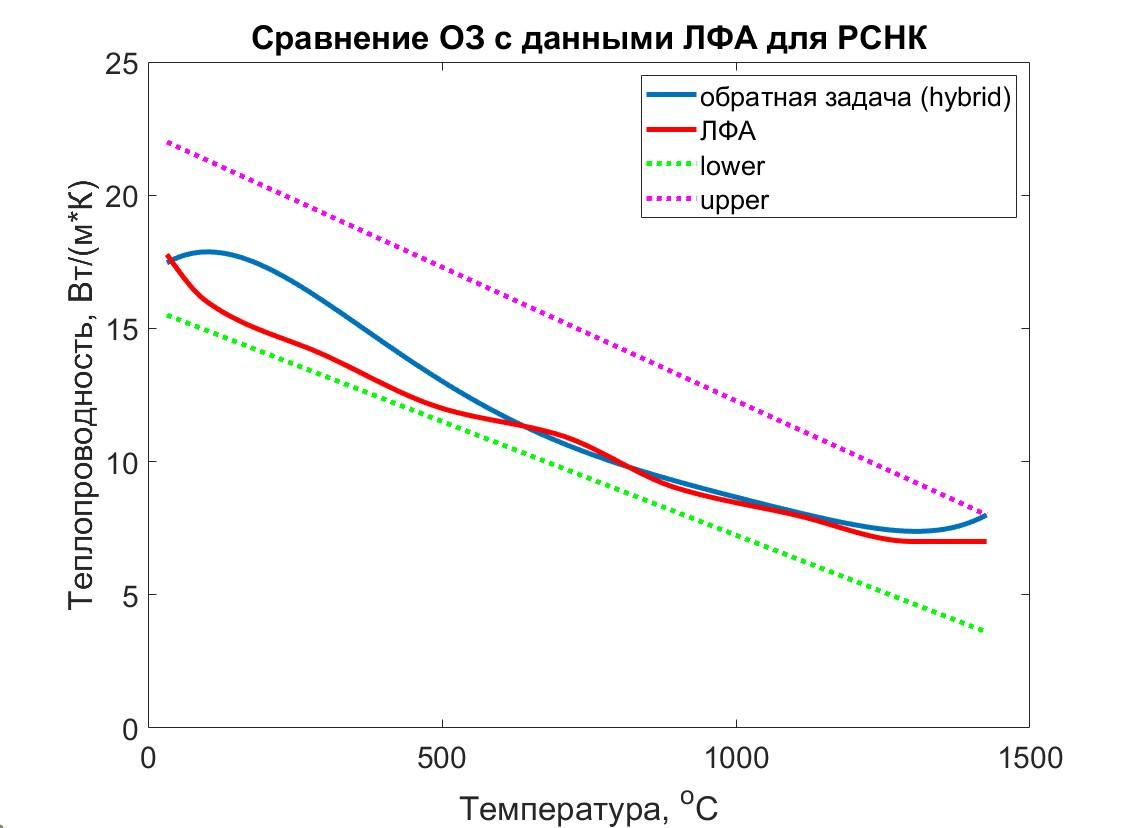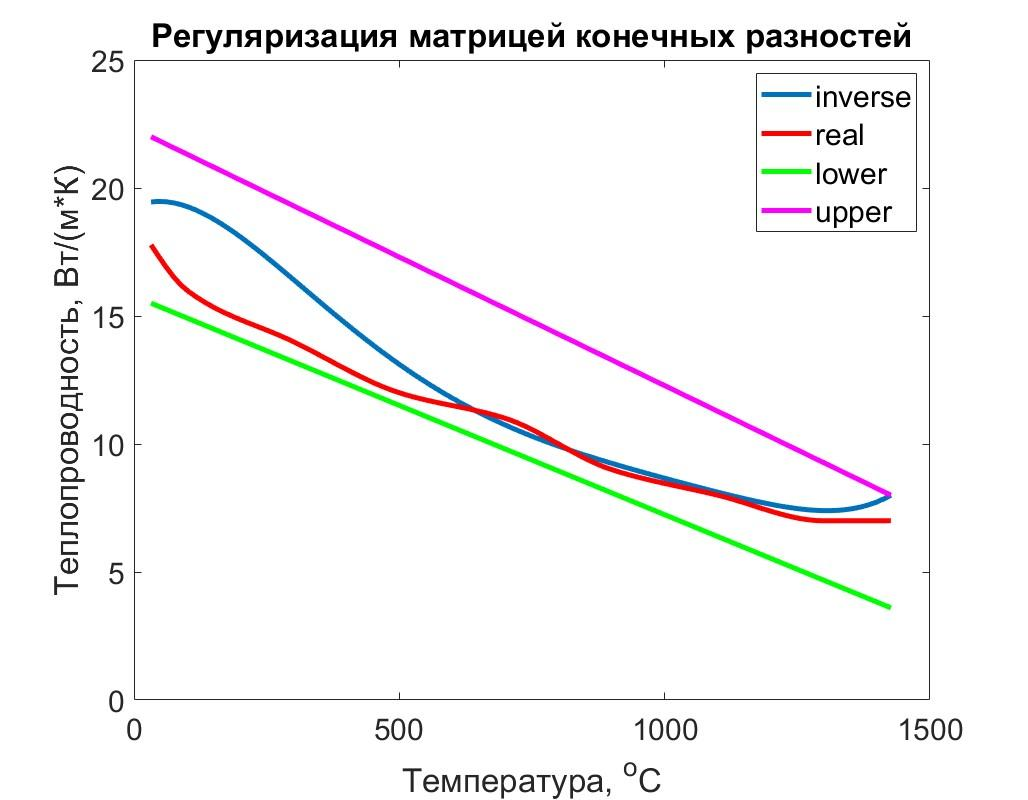

*Сравнение температурной зависимости теплопроводности восстановленной по экспериментальным данным с трех термопар с данным, полученными методом лазерной вспышки (слева обратная задача с регуляризацией единичной матрицей, справа - матричец конечных разностей). Температурная зависимость теплопроводности описывалась полиномами Бернштейна 8-й степени*

## Принцип максимального правдоподобия. Регуляризация при нелинейной оптимизации и метод Левенберга-Марвардта

Сегодня мы, во-первых, уйдем от обычного метода наименьших  квадратов (**O**rdinary **L**east **S**quares) и будем рассматривать более общие модели, как для линейной так и для нелинейной регрессии. Основным способом получения таких моделей является принцип максимального правдоподобия, основная идея которого состоит в том, чтобы найти такую оценку параметров модели,  которая наилучшим образом (с наибольшей вероятностью) предсказывает появляение тех данных, которые наблюдаются в эксперименте.  Кроме того целью будет проследить как работает регуляризация в задачах нелинейной регрессии.

## 1.Функция правдоподобия и принцип максимального правдоподобия

Пусть у нас есть некоторый набор экспериментальных точек в виде вектора $\vec{y}$ с $N$ элементами, которые являются независимыми выборками некоторой случайной величины, то есть все эти точки получены из одного распределения вероятности, характеризуемого набором параметров $\vec{b}$. Тогда вероятность получить наблюдаемый набор точек будет равна произведению вероятностей каждого из исходов ($y_i$) в отдельности:

$\mathcal{P}(\vec{y};\vec{b}) = \prod_{i=1}^Np(y_i ;\vec{b})$                                    (1)

$p(y_i|\vec{b})$ - вероятность получить точку со значением $y_i$ из некоторого распределения, характеризуемого набором параметров $\vec{b}$.

Если рассматривать вероятность как функцию параметров  $\vec{b}$, то она называется функцией правдоподобия.

$\mathcal{L}(\vec{b}|\vec{y}) =\mathcal{P}(\vec{y},\vec{b})$                                          (2)

Основная идея принципа максимального правдоподобия состоит в том чтобы находить такие параметры $\vec{b}$, которые максимизируют вероятность получить набор точек, измеренных в эксперименте:


$$\vec{b}_{MLE} = \mathrm{argmax}(\mathcal{L}(\vec{b}|\vec{y}))$$


MLE - maximum likelihood estimator

#### **Биномиальное распределение:**

$p(y | n, p) = \binom{n}{y} \psi ^y (1-\psi)^{n-y}, \quad y = 0,1,\dots,n$ - используется при анализе дисретных событий с бинарным исходом типа бросания монетки, $\psi$ - вероятность единичного положительного исхода, n - число бросаний.

 Значение плотности вероятности дает вероятность получить $y$ удачных исходов при n розыгрышах.

В качестве параметров  этого распределения будем рассматривать вероятность получения положительного исхода $p$ при единичном бросании. В качестве единичного  исхода $y_i$ будем рассматривать число выпадения "решки" при фиксированном числе бросков $n$. Функция правдоподобия рассчитывается по формулам (1,2).

%
clearvars
p_true =0.42;
N = 80;% число розыгрышей
M = 10;% число  бросаний в каждой точке
data = rand(N,M) < p_true
p =0.41;
bin_fun = @(k) nchoosek(M,k)*(p^k)*(1-p)^(M-k) ;
p_i = zeros(N,1);
y_i=  zeros(N,1);
for ii = 1:N
    y_i(ii) = sum(data(ii,:)); % число удачных бросаний в ii-м розыгрыше
    p_i(ii) = bin_fun(y_i(ii));% вероятность данного исхода
end
histogram(y_i)
xlabel("Число положительных исходов")
ylabel("Количество розыгрышей с данным исходом")
L = prod(p_i)

psi = 0:1e-3:1;
LikeliHoodFunc = @(d,p) prod(arrayfun(@(k) nchoosek(M,k)*(p^k)*(1-p)^(M-k), sum(d,2)))
Li = arrayfun(@(p_ii)LikeliHoodFunc(data,p_ii),psi)
plot(psi,Li)
xlabel("Параметр \psi")
ylabel("Функция правдоподобия, L(\psi)")
hold on
[lmax,indmax] = max(Li)
scatter(psi(indmax),lmax,"*r")
text(psi(indmax),lmax,string(psi(indmax)))
hold off

Максимизируется как правило логарифм функции правдоподобия (loglikelihood):


$$\mathcal{l}(\vec{b}) = log(\mathcal{L})$$


Либо минимизируется $-\mathcal{l}(\vec{b})$

logl_fn = @(p_ii)-log(LikeliHoodFunc(data,p_ii))
plot(psi,arrayfun(logl_fn,psi))
title("loglikelihood")

Одномерная оптимизация с ограничениями, чтобы найти параметр распределения

fminbnd(logl_fn,0,1)

#### Распределение Пуассона:

Как уже упоминалось, принцип максимального правдоподобия может исопльзоваться и для другой других функций распределения.

Распределение Пуассона:

$p(y | \lambda) = \frac{\lambda^y e^{-\lambda}}{y!}, \quad y = 0,1,2,\dots$ дает вероятность получения y редких событий, где параметр $\lambda$ - это среднее число событий. Например, если производится наблюдение за некоторым процессом во времени, то $\lambda$ будет средним числом событий за весь интервал времени, а y - это конкретное число событий.  

Предполаем события (измерения)  независимыми, соотвественно для формулировки функции правдоподобия мы можем пользоваться формулой.

Вектор экспериментальных данных $\vec{y}$, мы предполагаем, что каждая точка получена из распределения Пуассона со своим средним значением $\lambda_i$, так как мы хотим несмещенную оценку, наша модель должна, соотвественно, быть равна среднему значению для каждой из точек $f(\vec{b})_i = \lambda_i$. Функция правдоподобия:


$$\mathcal{L}(\vec{b}|\vec{y}) = \prod_i \frac{(f_i)^{y_i} e^{-f_i}}{y!}$$


loglikelihood:


$$\mathcal{l}(\vec{b}|\vec{y}) = \mathrm{log}(\prod_i \frac{(f_i)^{y_i} e^{-f_i}}{y_i!})= \sum_i[y_ilog(f_i) - log(y_i!)  - f_i] $$


Распределение Пуассона применяется для анализа редких событий, таких, как, например, возникновение брака в технологическом цикле. Имея, например, статистику разрушений изделий, можно построить модель для анализа тренда на уменьшение или увеличение количества брака.

clearvars
N = 30; % длительность наблюдения 
l0 = 4;
l1 = 1/N;
l2 = -5e-3/N;
l_true = [l2,l1,l0];
x = transpose(1:N);
lambda_true = polyval(l_true,x);% истинное изменение среднего значения от месяца к месяцу
y = arrayfun(@(lami)poissrnd(lami,1,1),lambda_true(:)); % вектор экспериментальных данных - число брака за 50 месяцев
table(y) % таблица количества брака в месяц
plot(x,y,"diamond");title("Число брака");xlabel("Месяц");ylabel("Штуки");
histogram(y);title("Число бракованных изделий");ylabel("Частота");xlabel("Число брака")

poisson_quality = 0;
polyfit_quality = 0;
pp_mean= 0;
pf_mean = 0;
trials_number = 5
for ii = 1:trials_number
    y = arrayfun(@(lami)poissrnd(lami,1,1),lambda_true(:));
    f_average = @(p) polyval(p,x);
    logl_fn = @(p) -sum(y.*log(f_average(p)) - log(gamma(y + 1)) - f_average(p)); % вместо факториала используем
% Гамма функцию, которая распространяет понятие факториала на все
% действительные числа
    poisson_regression = fminsearch(logl_fn,[1e-3,1e-2,3]); % решение задачи оптимизации
    polynomial_fit = polyfit(x,y,2); % обычный фитинг полиномом
    pp_mean = pp_mean + poisson_regression;
    pf_mean = pf_mean + polynomial_fit;
    poisson_quality = poisson_quality + norm(poisson_regression - l_true)/norm(l_true);
    polyfit_quality = polyfit_quality + norm(polynomial_fit - l_true)/norm(l_true);
end
poisson_regression = pp_mean/trials_number
polynomial_fit= pf_mean/trials_number
l_true

 poisson_quality= poisson_quality/trials_number
polyfit_quality= polyfit_quality/trials_number

plot(x,lambda_true);
hold on 
plot(x,f_average(poisson_regression));
plot(x,polyval(polynomial_fit,x));
hold off
legend(["Истинная","Пуассон", "Обычная регрессия"])
title("Сравнение оценки среднего ")


#### 2.Принцип максимального правдоподобия для решения задач регрессии при Гауссовой ошибке

У нас есть некоторая модель $f(\vec{\beta},\vec{x})$, которая зависит от набора параметров $\vec{\beta}$ и независимых переменных $\vec{x}$ . В задачах оптимизации, мы хотим найти оценку $\vec{b}$ истинных параметров модели $\vec{\beta}$ по измеренным данным  $\vec{y}$. Сама модель полагается верной и детерминированной, то есть, все отклонения измеренных данных от модели имеют случайную природу. Такми образом, можно сказать, что ошибка для каждого отдельного измерения получена из некоторого распределения.

Вопрос пригодности модели $f(\vec{\beta},\vec{x})$ для описания какого-то явления или процесса может быть изучен после решения задачи регрессии путем анализа справедливости исходного предположения регрессии - случайности ошибки регрессии. 

Пусть ошибка имеет нормальное распределение:

$ \mathcal{N}(0,1)$ - стандартное нормальное распределение (функция randn)

Чтобы получить переменную, взятую из $\zeta \sim \mathcal{N}(\mu,\sigma^2)$ из переменной, взятой из стандартного распределения $ \eta \sim \mathcal{N}(0,1)$


$$\zeta \sim \mathcal{N}(\mu,\sigma^2) = \mu + \sigma^2  \eta$$


Ошибка  равна разнице экспериментальных данных и предсказания модели для $i$ -й точки:


$$e_i= y_i - f(\vec{b})_i$$


Если ошибка берется из несмещеннjuj распределения (  $\mathcal{N}(0, \sigma^2)$ ), то для отдельного измерения: 


$$p(e_i) \propto p_0\exp\left( -\frac{1}{2} \frac{(y_i - f_i)^2}{\sigma^2} \right)$$


Это эквивалентно тому, что $y_i \sim \mathcal{N}(f_i,\sigma)$, то есть, сами точки получены из нормального распределения со средним значением $f_i$

Предполагая, что ошибки не зависят друго от друга, согласно формуле (1) для loglikelihood:


$$\mathcal{l}(\vec{b}) = \mathrm{log}(\mathcal{L})= \mathrm{log}( \prod_i^Np_0\exp\left( -\frac{1}{2} \frac{(y_i - f_i)^2}{\sigma^2} \right) = C  - \frac{1}{2\sigma^2} \sum_i^N (y_i - f_i)^2 = C-  \frac{1}{2}(\vec{y} - \vec{f})^T(\vec{y} - \vec{f})$$


При условии, что $\sigma^2$ постоянна для всех точек, мы получим обыкновенный метод наименьших квадратов (ordinary least squares).

Выражение для вероятности конкретного значения можно было бы переписать так:


$$\vec{y} \sim \mathcal{N}(\vec{f},\sigma I)$$


Прицип максимального правдоподобия может быть использован для оценки параметров модели даже если ошибка получена из  многомерного распределения Гаусса $\vec{y} \sim \mathcal{N}(\vec{\mu}, \Sigma)$, где:


$$\[
\mathcal{N}(\vec{y} \mid \vec{\mu}, \Sigma) = \frac{1}{(2\pi)^{\frac{d}{2}} |\Sigma|^{\frac{1}{2}}} \exp \left( 
-\frac{1}{2} (\vec{y} - \vec{\mu})^T \Sigma^{-1} (\vec{y} - \vec{\mu}) 
\right)
\]$$


Здесь $d$   - число измерений, $\Sigma$ - матрца ковариации размером (dxd), $\vec{\mu}$ - вектор средних значений по каждой из координат, $|\Sigma|$ - определитель матрицы ковариации.

MVG2 = @(x,mu,Sigma) exp(-(x(:)-mu(:))'*(Sigma\(x(:)-mu(:)))/2)/(2*pi*sqrt(det(Sigma))) % двумерное нормальное распредение
Sigma = [3,1;...
         1,2]
mu = [0;0]
try 
    det(Sigma);
    chol(Sigma);
catch ex
    disp(ex.message)
    disp("not positive defifnite")
    return
end
% Create grid for evaluation
x1 = -5:0.1:5;
x2 = -5:0.1:5;
[X1, X2] = meshgrid(x1, x2);
X = [X1(:), X2(:)];              %
Ngrid = size(X,1);
y = zeros(Ngrid,1);
for ii = 1:Ngrid
    y(ii) = MVG2(X(ii,:),mu,Sigma);
end
y = reshape(y, length(x2), length(x1));
surf(X1, X2, y);
xlabel('x_1'); ylabel('x_2'); zlabel('PDF');
title('Bivariate Gaussian Distribution');
colorbar; shading interp;
[u,s] = eig(Sigma)
u'*u
s = diag(s);
ax = get_next_ax()
contour(ax,X1,X2,y)
hold(ax,"on");
plot(ax,[mu(1);u(1,1)/s(1)],[mu(2),u(2,1)/s(1)],"Marker","o","Color","red","LineWidth",1)
plot(ax,[mu(1);u(1,1)],[mu(2),u(2,1)],"Marker","<","Color","red","LineWidth",1)
plot(ax,[mu(1);u(1,2)/s(2)],[mu(2),u(2,2)/s(2)],"Marker","*","Color","cyan","LineWidth",1)
plot(ax,[mu(1);u(1,2)],[mu(2),u(2,2)],"Marker","<","Color","cyan","LineWidth",1)
hold(ax,"off")
legend(ax,["","u1/\lambda_1","u1","u2","u2/\lambda_2" ])

В матлабе есть встроенная функция которая позволяет генерировать случаные вектора из гауссова распределения :

 mvnrnd(mu, Sigma) - первый аргумент - вектор средних, Sigma - матрица ковариации распределения

Помимо Гауссова, существует еще несколько распрделений, которые имеют подобную компактную форму для коррелированных данных, но для случая произвольного распределения получить такое простое выражение не удается.

#### Функция правдоподобия для коррелированной гаусовой ошибки:

$\mathcal{L}(\vec{b}|\vec{y})  \propto \mathrm{exp}(-\frac{1}{2}(\vec{f_b} -\vec{y})^T \Sigma^{-1}(\vec{f_b} - \vec{y}))$                                         (3)

$\Sigma$ - матрица ковариации входных данных, формула остается справедливой для коррелированных данных!

#### **Геометрия расстояния Махаланобиса**

Конструкцию, которая стоит в показатели экспоненты  называют *Mahalanobis distance*, она имеет смысл расстояния между двуия векторами $\vec{f_b}$ и $\vec{y}$.

Если вспомнить, что матрица ковариации является симметричной положительно-определенной, то матрицы ее собственных векторов являются ортонормированными,  спектральное разложение этой будет иметь вид: $\Sigma = U\Lambda U^T = \sum_d \lambda_d\vec{u}_d\vec{u}_d^T$ , где  $\vec{u}_d$ - собственные вектора матрицы ковариации , это единичные вектора показывающие направление главных осей информационной матрицы, тогда расстояние Махаланобиса между двумя векторами это:


$$\Sigma^{-1}  = \sum_d \frac{1} {\lambda_d}\vec{u}_d\vec{u}_d^T$$


Чем меньше $\lambda$ - большая вариация в данном направлении!


$$\vec{r}^T\Sigma^{-1}\vec{r} = \sum_d \frac{1}{\lambda_d}[\vec{r}^T\vec{u}_d][\vec{u}_d^T\vec{r}] = \sum_d \frac{z_d^2}{\lambda_d}$$


Вектора $\vec{u}_d$ - единичные вектора, следовательно

$z_d = \vec{r}^T\vec{u}_d$ - это длина проекции вектора разницы на главную ось эллипса.

t = table([[u(:,1),u(:,2)];[norm(u(:,1)),norm(u(:,1))];s']);
t.Properties.RowNames = string({'u(1)','u(2)','||u||','lambda'})

При решении обратных задач нестационарного теплопереноса, в качестве измеренных данных, выступают зависимости температур от времени, измеренный при нагреве образца, а в качестве параметров модели,  для коэффициентной ОЗ могут выступать, например, коэффициенты полиномиальной аппроксимации физических свойств материала (теплопроводности, теплоемкости), для граничной ОЗ коэффициенты аппроксимации теплового потока и т.п. 

Модель  $f(\vec{\beta},\vec{x})$ включает в себя, также решение прямой задачи - дифференциального уравнения в частных производных (в простейшем случае одномерного нестационарного) способ решения УЧП также имеет ряд параметров, таких как, например, дисретность сетки по времени и координате, которые в задаче регрессии напрямую не фигурируют, однако эти "скрытые" параметры также могут быть включены в задачу оптимизации.

#### Откуда берут матрицу $\Sigma$

Для нахождения матрицы $\Sigma$ используется априрорная инормация об ошибке исходных данных. Причем она  не обязана быть строгой матрицей ковариации, так как, в задаче регрессии $\Sigma$ это, в конечном счете, некоторый набор весов, который характеризует вклад отдельных точек ошибки в результирующую невязку.

**Эмпирическим  путем.**

Допустим, в качестве входных данных для ОЗ выступают термопарные измерения, полученные в ходе эксперимента. Например, зависимости температур от времени в нескольких точках образца $\vec{T}_k = T(x_k,t)$ - вектор из $M$ элементов . В этом случае  можно провести серию нагревов в одних и тех же (с экспериментальной точки зрения) условиях.Фактически в качестве оценки может быть использована воспроизводимость результатов измерений. Проведя $N$ измерений, получим матрицу $\Theta_k= [\vec{T^1} - <\vec{T}>,\dots,\vec{T^N} - <\vec{T}>]$, где  $<\vec{T}>$ - вектор усредненной по серии нагревов зависимости температуры от времени (вектор из $K$ элементов). Тогда матрицу ковариации можно оценить как:


$$\Sigma = \Theta_k\Theta_k^T/(N-1)$$


clearvars 
type = "diagonal"
M = 30;
N = 200;
if type=="diagonal"
    true_Sigma = diag(M:-1:1);
else
    [i, j] = meshgrid(1:M, 1:M);
    true_Sigma =30*exp(- abs(i - j)/10)
end
Ttrue = transpose(M*(1:M)); % средняя температура (истинная)
Thetta = zeros(M,N);
for ii = 1:N
    Thetta(:,ii) = Ttrue + mvnrnd(0*Ttrue, true_Sigma)';
end
Tavrgs_sample = mean(Thetta,2);
Thetta = Thetta - Tavrgs_sample;
Sigma_sample = Thetta*Thetta'/(N-1)
norm(true_Sigma - Sigma_sample)/norm(true_Sigma)
norm(true_Sigma)
surf(true_Sigma);title("True covariance")
surf(Sigma_sample); title("Sample covariance")

**Погрешность прибора.**

Например, для термопарных измерений, в качестве матрицы могут быть взяты погрешности термопарных измерений

Классы точности по ГОСТ Р 8.585-2001:

Для термопар типа S (ТПП, платина — 10% родий/платина) ГОСТ Р 8.585-2001 устанавливает два класса допуска: класс 1 (повышенная точность) и класс 2 (стандартный).

Погрешности для класса 1

- От 0 до 1100°C: ±1,0°C.

- От 1100 до 1600°C: ±[1,0 + 0,003(t - 1100)]°C, где t — температура в °C.

Погрешности для класса 2

- От 0 до 600°C: ±1,5°C.

- От 600 до 1600°C: ±0,0025t °C, где t — температура в °C.

Эти пределы представляют максимальную погрешность; для моделирования в ковариационной матрице можно использовать  $\sigma \approx \frac{\zeta}{3}$. 

**Эмпирические "предположени".**

Часто предполагают, что вариация прямо пропорциональна самому значению, тогда $\sigma = \psi T$, где $\psi$ это, например, 1е-2, тогда:


$$\Sigma = \psi\mathrm{diag}(\vec{T}^2) $$


**Данные с прибора, получаемые с прибора с конечным временем релаксации **$\tau$**.**

 Ясно, что если частота семплирования меньше времени релаксации, соседние точки по времени будут связаны друг с другом. Для определенности предположим, что речь идет об измерении температуры в зависимости от времени, термопара вместе имеет какое-то конечное время прогрева, а частота оцифровки сигнала с термопары может быть больше этого времени. Ошибка измерения складывается из двух составляющих, случайной ошибки ($e_i$) и ошибки "корреляции":


$$y_i = \vec{a}^T[\matrix{ y_1 \cr \vdots \cr y_{i-1}}] + e_i$$


Коэффициенты $\vec{a}$ корреляционной ошибки не должны зависеть от индеса вектора $\vec{y}$ (то есть от времени), а долны определяться толко некоторым интервалом времени, предшествующим точке $y_i$

 Тогда ковариация может быть представлена в виде функции с релаксацией:


$$\Sigma_{ij} = \sigma^2 \mathrm{exp}( - \frac{|t_i - t_j|}{\tau})=\sigma^2 \mathrm{exp}( - \frac{dt|i - j|}{\tau})$$


Такого вида матрицы, которые зависят от разницы индексов называются матрицами Тёплица, они имеют постоянные элементы на главной и побочной диагоналях (элементы -N и +N диагоналей не обязаны быть одинаковыми, то есть, квадратная матрица Тёплица не обязательно симметрична).

#### Пример. Линейная регрессия для данных коррелированных во времени.

Ошибка берется из гаусоова распределения с матрицей ковариации, соответсвующей коррелированным данным. И сравнивается взвешенная регрессия и обыкновенный метод наименьших квадратов.

clearvars
sigma2 = 0.01; % variance
tau = 3.89; % relaxation time
dt = 0.1; % sampling time < tau
N = 100; % number of samples
% toeplitz
Fs = 1/dt;
ff = Fs/N*(-N/2:N/2-1);
num_trials = 10;
t = (0:N-1)*dt;
[i, j] = meshgrid(1:N, 1:N);
Sigma = sigma2 * exp(- dt*abs(i - j)/tau) % 
V = [ones(N,1), t'];%, t'.^2,t'.^3];
p_true = [0.2, -1.4e-2]';%,0.14e-3,-0.14e-6]';
f_true = V*p_true;
cond(Sigma)
r_mse_weighted = 0;
r_mse_unweighted = 0;
for iii = 1:num_trials % чтобы увидеть эффект прогоним регрессию несоклько раз, так как для одного разад эффекта может и не быть
    y = f_true+ mvnrnd(0*f_true, Sigma)';  % Fixed transpose

    % weighted
    p_weighted = (V'* (Sigma \ V)) \ (V' * (Sigma \ y));

    % unweighted 
    p_unweighted = (V'*V) \ (V'*y);
    r_mse_weighted = r_mse_weighted + norm(p_weighted - p_true) / norm(p_true);
    r_mse_unweighted = r_mse_unweighted + norm(p_unweighted - p_true) / norm(p_true);
end
disp("Average RMSE:")
disp("Weighted =" + r_mse_weighted/num_trials);
disp("Unweighted =" + r_mse_unweighted/num_trials);

ax = get_next_ax();
scatter(ax,t',y)
hold(ax,"on");
plot(ax,t',V*p_true,"LineWidth",3);
plot(ax,t',V*p_weighted,"LineWidth",3);
plot(ax,t',V*p_unweighted,"LineWidth",3); 
hold(ax,"off")
legend(ax,["initial data", "weighted r="+ norm(p_true - p_weighted)/norm(p_true), ...
    "unwaighted r="+ norm(p_true - p_unweighted)/norm(p_true),"true"])
t = table(p_true,p_weighted,p_unweighted)
%,"ColumnNames",{'initial data', 'weighted','unwaighted'})
% covariance from fft
fft_y = abs(fftshift(fft(y)));
plot(ff,fft_y)

Видно, что, в среднем взвешенная регрессия выдает меньшую относительную ошибку оценки истинных значенйи параметров (хотя визуально так не скажешь)

При условии, что измерения независимы друг от друга, матрица ковариации будет диагональной: $W = (\matrix { \sigma_1^2 & \dots &0 \cr 0 & \ddots & 0 \cr 0 & \dots & \sigma_n^2})$, диагональные элементы - вариации для кажого из измерений. 

$W=\sigma I$, если все экспериментальные точки получены из одного и того же Гауссова распределения.

### 2.Функция невязки из принципа максимального правдоподобия для нелинейной регрессии в предположении Гауссовой ошибки

Все методы оптимизации,использующие данные о производной функции (как первого, так и второго порядков) строятся на вычислении производных первого и второго порядка, фундаментальных направлениях, антиградиента и шага Ньютона, поэтому вспомним основные соотношения.

Задача регресии  состоит в том, чтобы найти такой вектор параметров $\vec{b}$, который минимизирует скалярную функция невязки $\Phi(\vec{b})$ -   мера вектора ошибки:


$$argmin(\Phi(\vec{b}))$$


Вектор $\vec{r}$ - это разница между предсказанием модели ($f(\vec{b},\vec{x})$) и экспериментально наблюдаемым (или желаемым) постоянным вектором ($\vec{y}$).

Статистическими предположениями, будет, что ошибка получена из Гауссова распределения.

Далее используются следующие обозначения:

**ОФ** - общая формулировка 

**МЛГ** -  невязка, полученная из принципа максимального правдоподобия в предположении Гауссовой ошибки входных данных

**ВЛРГ** - взвешенная линейная регрессия частный случай модлели **МЛ** с линейной зависимостью от вектора параметров $f(\vec{b},\vec{x}) = A(\vec{x})\vec{b}$ (сама функция невязки $\Phi(\vec{b})$ при этом является квадратичной формой от параметров оптимизации.

$W = (\matrix { \sigma_1^2 & \dots &0 \cr 0 & \ddots & 0 \cr 0 & \dots & \sigma_n^2})$ - априорная матрица ковариации входных данных, диагональные элементы - вариации для кажого из измерений. Обыкновенный метод наименьших квадратов - это частный случай 

Далее будем обозначать функцию $f(\vec{b},\vec{x})$, рассчитанную для каждого значения вектора $\vec{x}$ как $\vec{f_b}$

**МЛ**: $\Phi(\vec{b})=\frac{1}{2} \vec{r}W^{-1}\vec{r}= \frac{1}{2} (\vec{f_b} -\vec{y})^T W^{-1}(\vec{f_b} - \vec{y})$ 

$f$ - некоторая нелинейная функция от вектора параметров оптимизации при заданной независимой переменной $\vec{x}$, возвращающая вектор значений для каждого значения независимой переменной.   

**ЛР:** $\Phi(\vec{b})=\frac{1}{2} (A\vec{b}-\vec{y})^T  W^{-1}(A\vec{b}-\vec{y})$ - МНК для линейной регрессии ($A$ - постоянная матрица, например для полиномиального вида функции это матрица Вандермонда)

Итерационная оптимизация, подразумевает, что из текущего положения в пространстве параметров$\vec{b}_{k}$ перейти в новую точку $\vec{b}_{k+1}$, которая будет ближе к точке локального минимума $\vec{b}^*$:


$$\vec{b}_{k+1} = \vec{b}_{k} +\vec{p_{k}}(\vec{b}_{k}\dots)$$


Вектор шага между итерациями ($\vec{p}$) рассчитывается в соответствии с алгоритмом.

3.Метод градиентного поиска (метод первого порядка):

Как известно вектор градиента функции направлен в сторону ее максимального роста, следовательно вектор антиградиента направлен в сторону уменьшения:

**ОФ**: $\vec{p}^k_{gradient\ descend}=- \mu \hat{g}(\vec{b}^k) $ 

$ \hat{g}(\vec{b})= \frac {\nabla_b \Phi(\vec{b})}{||\nabla_b \Phi(\vec{b})||}$ -  вектор единичной длины, направленный в сторону  антиградиента

**МЛ**: $\nabla_b \Phi(\vec{b}) = J^TW^{-1}(\vec{f_b} - \vec{y})$

 $J $ - матрица Якоби, для которой $J_{ij} = \frac {\partial f_b }{\partial b_j} (x_i)$, то есть, на $i$-й строке стоит градиент функции $\nabla_b f(\vec{b},x_i)$

**ЛР**: $\nabla_b\Phi(\vec{b}) = A^TW^{-1}(A\vec{b}-\vec{y})$ 

для задачи линейной регрессии, $J=A$. Условие равенства нулю градиента дает нормальное уравнение для решения задачи линейной взвешенной регресси: $\vec{b} = (A^TW^{-1}A)^{-1}A^TW^{-1}\vec{y}$

Метод Ньютона (метод второго порядка):

**ОФ**:$ \vec{p}_{Newton} = - (\nabla_b^2\Phi(\vec{b},\vec{x}))^{-1}\nabla_b \Phi(\vec{b},\vec{x}) $

**МЛ**: $\nabla_b^2 \Phi(\vec{b}) = J^TW^{-1}J + H= J^TW^{-1}J + \sum_q H(x_q)r_q$, где $H_{ij}(x_q) = \frac {\partial^2 f}{\partial b_i \partial b_j}(x_q)$ - матрица вторых производных, рассчитанная в точке $x_q$

$ \vec{p}^k = -  ( J^TW^{-1}J + H)^{-1}J^TW^{-1}(\vec{f_b^{k}} - \vec{y})$ - шаг в методе Ньютона

**ЛР: **$\nabla_b^2 \Phi(\vec{b}) = A^TW^{-1}A$, так как вторые производные от квадратичной формы равны нулю 


$$ \vec{p} = -  ( A^TW^{-1}A)^{-1}A^TW^{-1}(A\vec{b}-\vec{y})$$


Проблемы метода Ньютона: Если матрица Гесса $\nabla_b^2 \Phi(\vec{b})$ не является положительно-определенной, то метод будет шагать не в ту сторону (можно проверить путем перемножения с вектором антиградиента, если скалярное произведение отрецательно, то угол с антиградиентом тупой, значит шагаем мы в сторону от минимума). Кроме того, матрица Гесса может оказаться сингяларной! Тогда непонятно куда шагать, есть бесконечно много вариантов.

Метод Гаусса-Ньютона :

Получается если в шаге по методу Ньютона пренебречь матрицей вторых производных, а оставить только перекрестное произведение первых $\nabla_b^2 \Phi(\vec{b}_i) \approx J^TJ$(это может быть выгодно, так как матрица Якоби и так считается для расчета первой производной, а для шага Ньютона нужны и градиент,и Гессиан). 

Данная аппроксимация матрицы Гесса часто исользуется на практике, так как она не требует вычисления вторых производных

**ОФ**: -

**МЛ**: $\nabla_b^2 \Phi(\vec{b}_i) \approx J^TW^{-1}J$

**ЛР: **$\nabla_b^2 \Phi(\vec{b}_i) = A^TW^{-1}A$

$ \vec{p} = -  ( A^TW^{-1}A)^{-1}A^TW^{-1}(A\vec{b}-\vec{y})$ для линейной регрессии шаг Гаусса-Ньютона не отличается от шага Ньютона так как вторые производные равны нулю.

В методе Гаусса - Ньютона приближенный Гессиан всегда положительно-полуопределенный, но все равно он может оказаться сингулярным или близким к сингулярному, тогда, как мы видели на прошлом семинаре метод потимизации будет неустойчивым.

#### Оптимизация градиентными методами при регуляризации 

Добавим в исходную невязку регуляризующий член в общем виде :

$\Gamma$ - некоторая матрица, такая что $\Gamma^T\Gamma$  - положительно определенная, $\alpha$ - скалярный регуляризующий множитель


$$\Phi(\vec{b})=\frac{1}{2} \vec{r}W^{-1}\vec{r}= \frac{1}{2} (\vec{f_b} -\vec{y})^T W^{-1}\ (\vec{f_b} - \vec{y}) + \frac{1}{2}\alpha\vec{b}^T\Gamma^T\Gamma\vec{b}$$
 

$\nabla_b \Phi(\vec{b}) = J^TW^{-1}\vec{r} + \alpha \Gamma^T\Gamma\vec{b}$ - градиент регуляризованной задачи

Матрица Гесса регуляризованной задачи:


$$\nabla_b^2 \Phi(\vec{b}) = J^TW^{-1}J + \sum_q H(x_q)r_q + \alpha \Gamma^T\Gamma$$


Соотвественно, шаг в методе Ньютона:


$$ \vec{p}_{newton} = -  ( J^TW^{-1}J + H  + \alpha\Gamma^T\Gamma)^{-1}(J^T W^{-1}\vec{r}+ \alpha \Gamma^T\Gamma \vec {b})$$


Если в этом выражении воспользоваться приближенным гессианом (метод Гаусса-Ньютона) то получим:


$$ \vec{p}_{G-N} = -  ( J^TW^{-1}J +  \alpha\Gamma^T\Gamma)^{-1}(J^T W^{-1}\vec{r}+ \alpha \Gamma^T\Gamma \vec {b})$$


Как мы помним из предыдущих семинаров (J.Nocedal and S.J.Wright (2006). Numerical optimization, Springer.), чтобы направление шага было в сторону локального минимума,  движение алгоритма должно производиться в направлении, вектор которого, образует острый угол с направлением антиградиента. Однако, так как регуляризация вносит дополнительную составляющую в вектор градиента, то при достаточно большом параметре регуляризации, даже метод градиентного поиска может начать идти не в "ту сторону". Это, логично, так как, мы добавили в невязку составляющую $\alpha \Gamma^T\Gamma \vec {b}$ , стремящуюся уменьшить длину вектора параметров, поэтому при достаточно большом параметре регуляризации эта составляющая начнет превалировать над основной $(\vec{f_b} -\vec{y})^T W^{-1}\ (\vec{f_b} - \vec{y})$ и алгоритм повернется в сторону нуля модуля вектора параметров $\vec {b}^T \vec {b}$.

**Почему при расчете матрицы Гесса пренебрегают матрицей вторых производных?**

$\nabla_b^2 \Phi(\vec{b}) = J^TW^{-1}J + H= J^TW^{-1}J + \sum_q H(x_q)r_q$, где $H_{ij}(x_q) = \frac {\partial^2 f}{\partial b_i \partial b_j}(x_q)$ 

$J$ - матрциа размером $M\times  P$, где $M$ - длина вектора невязки, а $P$ - число переменных оптимизации, обычно $M>>P$, чтобы ее посчитать надо рассчитать $P$ производных в $M$точках, пусть мы используем конечные разности, вычисление потребует $M(P +1)$ вычислений функции $f$. Вычисление матрицы вторых производных требует варьирования двух координат вектора параметров, то есть, оно будет стоить уже $M P^2$.

Как правило, оказывается выгоднее сделать $P$ шагов в направлении приближенного шага Ньютона, чем рассчитывать матрицу Гесса полностью.

### Метод Левенберга-Марквардта

Метод ЛМ является достаточно распространенным методом решения задач нелинейной оптимизации, благодаря "встроенной" регуляризации данных метод является одним из наиболее часто используемых (наравне с методом сопряженных градиентов) для решени ОЗ теплопроводности. Поэтому остановимся на нем подробнее.

Идея метода довольно проста, давайте использовать метод Гаусса-Ньютона, но с параметром из метода с регуляризацией, но параметр регуляризации будем подбирать на каждом шаге свой, плюс, так как проблемы с методом Гаусса - Ньютона могут быть только из-за Гессиана,будем подбирать только его.

#### Шаг алгоритма и регуляризующая матрица


$$ \vec{p}_{L-M}^k = -  ( J^TW^{-1}J +  \lambda^k \Omega^k)^{-1}J^T W^{-1} (\vec{f_b} - \vec{y})$$


Где регулризующая положительно-определенная матрица ($\Omega^k$) и параметр $\lambda^k$ на каждой итерации свои. Добавление положительно-определенной матрицы $ \lambda^k \Omega^k$:

-  Делает приближенный Гессиан положительно определенным, а также уменьшает **conditional number**

- Благодаря тому, что подбор регулризующего множителя производится внутри метода на текущий итерации производится подбор параметра $\lambda$ , то есть направления поиска таким образом, делается пробный шаг, как в стратегии **line-search **и смотрится есть ли достаточное уменьшение значения функции, если шагнуть в этом направлении. Так как направление шага при этих пробных шагах меняется, то это уже не линейных поиск (line-search), подобную стратегию поиска следующего шага называют **trust region**.  

При решении обратных задач теплопереноса в  Л-М используют не единичную матрицу, а диагональ самого приближенного гессиана: 


$$\Omega^k=\mathrm{diag}((J^k)^TW^{-1}J^k)$$


То есть, в качестве регуляризующей матрицы используются сами диагональные элементы приближенной матрицы Гесса. 

### Погрешность оценки параметров модели

#### 1.Матрица ковариации линейной регрессии

Для линейной регрессии

$\mathrm{argmin}(\vec{e}^T\vec{e})$, где


$$\vec{e} = \vec{y} - A\beta$$


Вектор ошибки имеет нулевое среднее и матрицу ковариации $\Sigma = \vec{e}^T\vec{e}$

Матрица ковариации для  метода наименьших квадратов с весовой матрицей $W$(весовая матрица - это некоторое априорное представление о ковариации исходных данных):


$$\vec{b}=A^{\dagger}\vec{Y}=A^{\dagger}A\vec{\beta} + A^{\dagger}\vec{\epsilon}=\vec{\beta} + A^{\dagger}\vec{\epsilon}$$


$A^{\dagger} = (A^TW^{-1}A)^{-1}A^TW^{-1}$ - тут видно что весовая функция задается с точностью до некоторой постоянной

$\mathbb{E}[\vec{b}]=\vec{\beta}$, так как $A^{\dagger}A=(A^TW^{-1}A)^{-1}A^TW^{-1}A=I$, а $\mathbb{E}[\vec{\epsilon}]=\vec{0}$, мы предполагаем, что среднее ошибки равно нулю.


$$Cov(\vec{b})=(\vec{\beta}-\vec{b})(\vec{\beta}-\vec{b})^T=((A^{\dagger}A-I)\vec{b} + A^{\dagger}\vec{\epsilon})((A^{\dagger}A-I)\vec{b} + A^{\dagger}\vec{\epsilon})^T=A^{\dagger}\vec{\epsilon}\vec{\epsilon}^T(A^{\dagger})^{T}$$



$$\mathrm{Cov}(\vec{b}) = A^{\dagger}\Sigma(A^{\dagger})^{T} = [(A^TW^{-1}A)^{-1}A^TW^{-1}]\Sigma [(W^{-1})^TA(A^TW^{-1}A)^{-1}] $$


Если измерения некоррелированы , но каждая точка получена из распределения со своей дисперсией, то матрица ковариации $\Sigma$ будет диагональной , тогда выражение для матрицы ковариации можно переписать в виде:


$$\mathrm{Cov}(\vec{b})= (A^TW^{-1}A)^{-1}
\Sigma= (A^TW^{-1}A)^{-1}
[\matrix { \sigma_1 & \dots & 0 \cr 
0 & \ddots & 0 \cr
0 & \dots & \sigma_N} ]$$


Если все экспериментальные точки получены из одного распределения с дисперсией $\sigma^2$, то вышеприведенная формула перейдет в стандартную:


$$\mathrm{Cov}(\vec{b}) =(A^TA)^{-1}\sigma^2$$


Эта формула дает матрицу ковариации для среднеквадратичной оценки параметров модели для обыкновенного метода наименьших квадратов

#### Матрица ковариации для нелинейной регрессии

Для линейной регресии матрица ковариации оценки параметров модели:

$\mathrm{Cov}(\vec{b})= \mathbb{E}((\vec{b} - \vec{\beta})(\vec{b} - \vec{\beta})^T) = (A^TW^{-1}A)^{-1}\zeta^2$ - матрица ковариации

При этом матрица Гесса $\nabla_b^2 \Phi(\vec{b}) = A^TW^{-1}A$

Для нелинейной задачи, для оценки ковариации используют матрицу Гесса, рассчитанную в точке локального минимума:

$\mathrm{Cov}(\vec{b}^*)= \mathbb{E}((\vec{b} - \vec{\beta})(\vec{b} - \vec{\beta})^T) = (J^TW^{-1} J+ H)^{-1}\zeta^2$ - матрица ковариации

Причем, как правило пренебрегают вторыми производными оставляя только перекрестные произведения:

$\mathrm{Cov}(\vec{b}) \approx (J^T W^{-1} J)^{-1}\zeta^2$ - матрица ковариации

Величина дисперсии $\zeta^2$ - неизвестна, поэтому для ее оценки используют квадратичное отклонение аппроксиамции:

$\zeta^2 \approx \frac{ (\vec{f}_{b^*} - \vec{y})^T W^{-1} (\vec{f}_{b^*} - \vec{y}) } {N-P}$  - экспериментальная оценка вариации

Величину, обратную матрице ковариации еще называют информационной матрицей Фишера.

[folder,name] = fileparts(matlab.desktop.editor.getActiveFilename);
addpath(fullfile(folder,name+"_deps"));

### Оценка правильности выбранной модели

Важны вопросом является оценка правильности выбранной модели, то есть, допустим есть несколько моделей, отличающие количеством параметров, нужно выбрать ту, которая более соотвествует описываемому процессу. Если речь идет, например о полиномиальной аппроксимации, то полиномом высокой степени можно описать данные с очень высокой точностью, то есть,  когда степень полинома равна количеству экспериментальных точек, можно получить нулевую сумму квадратов ошибки и можно сделать вывод о нулевой вариации. 

Основные характеристики:

$SSE=RSS = \sum_{i=1}^N(y_i - \hat{y}_i)^2$ - сумма квадратов ошибки регрессии (сумма квадратов остатков), $N$ - число экспериментальных точек, $\vec{y}$ - вектор экспериментальных точек, $\vec{\hat{y}}$ - вектор предсказаний модели;

 $\hat\sigma^2 = \frac{ \sum_{i=1}^N(y_i - \hat{y}_i)^2}{N-P} = \frac{SSE}{N-P}$ - экспериментальная оценка дисперсии ошибки регресии, $P$ - число параметров модели, $N-P$ - число степеней свободы пространства  ошибки.

$SST =TSS= \sum_{i=1}^N(y_i -<\vec{y}>)^2$ - общая сумма квадратов (она эквивалентна линейной регрессии с одним параметром, то есть отклонению от среднего).

$s^2 = \frac{SST}{N-1}$ - дисперсия выборки 

$r^2 = 1 - \frac{SSE}{SST}$ - эр-квадрат (коэффициент детерминации), характеризует то насколько модель лучше фитит данные, чем просто расчет среднего, если $SSE=SST$ то $r^2=0$ , это значит что наша модель не лучше расчета среднего.

$adjusted\ r^2 = 1 - \frac{\sigma^2}{s^2} = 1 - \frac{SSE}{SST}(\frac{N-P}{N-1})$ - эджастед эр-квадрат (корректированный коэффициент детерминации)

clearvars
n = 150;
noise = 0.073;
p = [1,3,10];
p_true = [0.079,-0.14,4];
x = linspace(0,1,n)';
y = polyval(p_true,x) + noise*randn(n,1);

pps = cell(numel(p),1);
stats = cell(numel(p),1);
ax = get_next_ax();
ax_hist = get_next_ax();
ax_res = get_next_ax();

plot(ax,x,y,"-ob")
hold(ax,"on");hold(ax_hist,"on");hold(ax_res,"on");
y_hat = zeros(n,numel(p));
for ii = 1:numel(p)
    pps{ii} = polyfit(x,y,p(ii)-1);
    y_hat(:,ii) = polyval(pps{ii},x);
    cur_stat = descriptive_stat("y",y,"y_hat",y_hat(:,ii),"p",p(ii));
    stats{ii} = cur_stat;
    plot(ax,x,y_hat(:,ii))
    histogram(ax_hist,y - y_hat(:,ii),30,"Normalization","probability","FaceAlpha",0.3)
    plot(ax_res,x,y - y_hat(:,ii),"MarkerMode","auto")
end
hold(ax,"off");hold(ax_hist,"off");hold(ax_res,"off");
legend(ax_res, string(p)); ylabel(ax_res,"Ошибка");xlabel(ax_res,"Координата");title(ax_res,"Ошибка регрессии")
legend(ax_hist, string(p));ylabel(ax_hist,"Доля");xlabel(ax_hist,"Отклонение");title(ax_hist,"Распределение ошибки")

names = fieldnames(stats{1})
stat_data = zeros(numel(p),numel(names));
for ii = 1:numel(p)
    disp("p=" + p(ii))
    fitdist(y-y_hat(:,ii),"Normal")
    
    stat_data(ii,:) = cellfun(@(X)stats{ii}.(X),names);
end

t = array2table(stat_data);
t.Properties.VariableNames = names;
t.Properties.RowNames = string(num2cell(p))
axbar = get_next_ax();
bar(axbar,t.RIC,"FaceAlpha",0.3);hold(axbar,"on")
bar(axbar,t.AIC,"FaceAlpha",0.3)
bar(axbar,t.AICC,"FaceAlpha",0.3)
bar(axbar,t.BIC,"FaceAlpha",0.3)
hold(axbar,"off");legend(axbar,["RIC","AIC","AICC","BIC"]);
%ylim(axbar,[-2500,-2200])
axbar.XLabel.String = cellstr(["p=" + p(1),"p=" + p(2),"p=" + p(3)]);

Поэтому выбор оптимальной модели основан на двух критериях: хорошего описания модели (малая амплитуда ошибки) и простоты выбранной модели (малое число параметров модели).

Для линейной регрессии существует несколько достаточно простых критериев, основаны на анализе  ошибки регрессии, в формулах ниже $k$ - это число параметров модели, $n$ - число точек.


$$\hat{\sigma}^2=\frac { \vec{r}^T\vec{r}} {n}$$


AIC: $n\mathrm{log}(\hat{\sigma}^2) + 2k + n(1+ln(2\pi))$ - Akaike information criteria

BIC: $n\mathrm{log}(\hat{\sigma}^2) + k\mathrm{log}(n) + n(1+log(2\pi))$ - Bayesian information criteria

AICc: $AIC + \frac{2k(k+1)}{n-k-1}$ -corrected Akaike information criteria

RIC: $(n-k)\mathrm{log}(\hat{\sigma}^2) + k[\mathrm{log}(n) - 1] + \frac{4} {n-k-2}$ (J.R.Statist.Soc.B 2002. pp. 237 - 252. Regression model selection  - a residual likelihood approach,  в статье формула выводится в более общем виде, который позволяет ее использовать для различного вида регрессий, так называемых **G**eneralized **L**inear **M**odel, для которых также как и для обычной линейной регерсии существуют аналитические решения)

AICf = @(n,k,s)n*log(s) + 2*k %+ n*(1 + log(2*pi))
BICf = @(n,k,s)n*log(s) + k*log(n) %+ n*(1 + log(2*pi))
AICCf = @(n,k,s) n*log(s) + 2*k.*(k+1)./(n - k - 1);
RIC = @(n,k,s)(n-k)*log(s) + k*(log(n)-1)  + 4./(n - k - 2);
M = {AICf,BICf,AICCf,RIC};

n = 18;
k = 33;
r = 2.9;
s  = r/(n - k);
n_range = k+2:100;
k_range = 1:n-2;
s_range = 1e-4:1e-2:3;
lstr = ["AIC","BIC","AICC","RIC"]
plot(n_range,AICf(n_range,k,s),"r", ...
    n_range,BICf(n_range,k,s),"g",...
    n_range,AICCf(n_range,k,s),"b",...
    n_range,RIC(n_range,k,s),"c",LineWidth=2)
legend(lstr,"Location","best");xlabel("Число точек");title("k=" + string(k) + ", SSE =" + s)
plot(k_range,AICf(n,k_range,s),"r", ...
    k_range,BICf(n,k_range,s),"g",...
    k_range,AICCf(n,k_range,s),"b",...
    k_range,RIC(n,k_range,s),"c",LineWidth=2)
legend(lstr,"Location","best");xlabel("Число параметров");title("n=" + n + ", SSE =" + s)
plot(s_range,AICf(n,k,s_range),"r", ...
    s_range,BICf(n,k,s_range),"g",...
    s_range,AICCf(n,k,s_range),"b",...
    s_range,RIC(n,k,s_range),"c",LineWidth=2)
legend(lstr,"Location","best");xlabel("SSE");title("n=" + n + ", k =" + k)


AICf = @(n,k,s)n*log(s) + 2*k %+ n*(1 + log(2*pi))
BICf = @(n,k,s)n*log(s) + k*log(n) %+ n*(1 + log(2*pi))
AICCf = @(n,k,s) n*log(s) + 2*k.*(k+1)./(n - k - 1);
RIC = @(n,k,s)(n-k)*log(s) + k*(log(n)-1)  + 4./(n - k - 2);
M = {AICf,BICf,AICCf,RIC};


n = 100;
e = 0.25
x = linspace(0,1,n)';
p_true = [8e-1, 1e-2,1];
k = [1,2,3,4,5,6,10];
m = length(M); % number of criteria
q = length(k);% number of models
y = cell(m ,1);
p = cell(m ,1);
r = zeros(m ,1);
y_true =  (1 + (e/100)*randn(n,1)).*polyval(p_true,x);

plot(x,y_true,"-o");title("Исходная функция")
for ii = 1:q
    ki = k(ii);
    p{ii} = polyfit(x,y_true,ki - 1);
    y{ii} = polyval(p{ii},x);
    r(ii) = sumsqr(y{ii} - y_true);
end
criteria_value = zeros(q,m);
for jj = 1:m
    cr_fun = M{jj};
    for ii = 1:q
        ki = k(ii);
        ri = r(ii)/(n-ki);
        criteria_value(ii,jj) =cr_fun(n,ki,ri);
    end
end
ax2 = get_next_ax();
plot(ax2,k,criteria_value,LineWidth=2,MarkerMode="auto")
xlabel("Число параметров модели")
ylabel("Значение критерия")
legend(lstr,"Location","best");
% p2 = polyfit(x,y,2);y2 = polyval(p2,x);
% p3 = polyfit(x,y,3);y3 = polyval(p3,x);
% p4 = polyfit(x,y,4);y4 = polyval(p4,x);
% ax = get_next_ax();
% 
% plot(ax,x,y,"*r",...
%             x,y2,"-ob",...
%             x,y3,"-og",...
%             x,y4,"-ob")
% 
% 
% AIC_val = AIC(n,length(p))
% BICf = @(n,k,s)n*log(s) + k*log(n) %+ n*(1 + log(2*pi))
% AICCf = @(n,k,s) n*log(s) + 2*k.*(k+1)./(n - k - 1);
% RIC

### Планирование эксперимента.

Основная идея задачи планирования состоит в том, чтобы поставить эксперимент таким образом, чтобы уменьшить неопределенност в выходных параметрах (см формлуы для ковариации линейной и нелинейной регресии). Понятно, что неопределенност можно уменьшить увеличивая величину дисперсии исходных данных путем увеличения числа измерений, но это не всегда возможно, а вот повлиять постановкой эксперимента на величину матриц $A^TA$ и $J^TJ$ в принципе возможно.

Таким образом задача планирования эксперимента это оптимизационная задача по подбору условий получения исходных данных, таким образом, чтобы получить минимально возможную вариацию параметров.

#### Планирования эксперимента на примере линейной регрессии

Начнем с более простого варианта  - линейной регресии. 

Рассмотрим конкретный пример.

Для определенности, пусть у нас есть некоторый процесс, за которым мы можем наблюдать во времени, мы предполагаем, что этот процесс описывается кубическим полиномом  (в стандартном базисе) от времени, то есть, измеряемый датчиком отклик: $y = a_0 + a_1t + a_2t^2 + a_3t^3 + \zeta$, для простоты предположим, что ошибка измерений не зависит от времени, тогда можно пользоваться обычной регрессией. Пусть длительность процесса будет одна секунда  $t \in [0\dots1]$. Для наблюдения за процессом мы используем  автономный датчик, который может в течение  1 секунды снять только десять точек (после чего у него "садится" батарейка), зато частота расположения этих точек может быть произвольной,поэтому мы можем получить измерения для любых десяти моментов времени в пределах одной секунды. Задача проектирования эксперимента будет состоять в том, чтобы подобрать такую зависимость интервала между считываниями, чтобы получить минимальную вариацию параметров модели $\vec{a} = [a_0...a_3]$, то есть, найти такие моменты времени включения датчика $t_i$, которые позволят нам максимально достоверно (с наименьшей вариацией) оценить вектор параметров модели. 

Матрица предикторов для полиномиальной аппроксимации будет:


$$X = [I,\vec{t}, \vec{t}^2, \vec{t}^3]$$


Ковариация оценки параметров модели:


$$\mathrm{Cov}(\vec{a}) = (X^TX)^{-1}\sigma^2$$


Отсюда видно, что, чем "больше" и "устойчивей"  информационная матрица $X^TX$, тем "меньше" ковариация (а диагональные элементы этой матрицы - это вариация)  - меньше неопределенности нашей оценки параметров. Поэтому можно поставить оптимизационную задачу проектирования: найти такой набор параметров$\vec{\theta}$, который дает максимальную информационную матрицу  $X(\vec{\theta})^TX(\vec{\theta})$ или минимальную матрицу ковариации $\mathrm{Cov}(\vec{a}) \propto (X(\vec{\theta})^TX(\vec{\theta}))^{-1}$

Что такое "максимальная/минимальная" матрица, тут можно применить разные критерии:

-  D - оптимальность: Чем больше определитель информационной матрицы (меньше определитель обратной), тем меньше объем эллипсоида неопределенности: $\vec{\theta} = \mathrm{argmin( det((X^TX)^{-1})}$. Хотя уменьшение вариации это хорошо, но в данном критерии возможно появление неустойчивости  из-за большого 

-  K - оптимальность.Чем меньше conditional number (отношение максимального сингулярного знаечния к минимальному) информационной матрицы, тем более устойчиво ее обращение: $\vec{b} = \mathrm{argmin(cond(X^TX))$

- A - оптимальность. Чем меньше след обратной информационной матрицы, 

 Будем пытаться найти функцию, которая наилучшим семплирует из трех видов: первая  семплирование:

$\vec{t}^{uniform} = (\vec{i} - 1)/(n-1)$ - равномерное

$\vec{t}^{exp}(\gamma) = \frac {exp({\gamma\vec{t}^{uniform}) - 1}} {exp({\gamma) - 1}}$ - экспоненциальное с параметром $\gamma$

$\vec{t}^{cheb} =\frac{1}{2} cos(\frac{\pi(\vec{i}-1)}{n-1})$  - семплирование по Чебышеву


$$\vec{i} = [1\dots n]^T$$


Вообще данная задача, конечно уже давно решена, самую лучшую матрицу дает семплирование по Чебышеву с полиномами чебышева в качестве мономиалов, поэтому данный вариант мы будем рассматривать как эталонный

clearvars
X_fun = @(g,f) [ones(10,1),f(g),(f(g)).^2,(f(g)).^3]; % experiment matrix
inform_mat = @(g,f) ( X_fun(g,f)' *   X_fun(g,f));% information matrix
f_discr_cond = @(g,f) cond(inform_mat(g,f)); % minimizing conditional number
f_discr_det = @(g,f) det(inform_mat(g,f)\eye(4)); % 
f_discr_trace = @(g,f) trace(inform_mat(g,f)\eye(4));


n = 10; % number of sampling points
ii = (1:n)';
tmin = 0;
tmax = 1;
t0 = tmin + (tmax - tmin)*(ii - 1)/(n-1); % equally spaced sampling procedure
tcheb = chebyshev_nodes(n,tmin,tmax);
X_equally =[ones(10,1),t0,t0.^2,t0.^3]; % predictors for equally spaced sampling points
%X_cheb = [ones(10,1),tcheb,tcheb.^2,tcheb.^3];
X_cheb = cheb_vandermonde(tcheb,3)
gamma=4.171;
f_exp_spaced = @(gamma) tmin + (tmax - tmin)*(exp(gamma*t0) - 1)/(exp(gamma) -1);
ax = get_next_ax();
plot(ii,t0,"-*r")
hold on
plot(ax,ii,f_exp_spaced(gamma),"-ob")
plot(ax,ii,tcheb,"-*g")
hold off
ylabel("Момент времени регистрации")
xlabel("Номер точки")
legend(["fixed, dt ="+ (t0(2) - t0(1)), ...
    "exp, dt =[" + min(abs(diff(f_exp_spaced(gamma)))) + "..." + ...
    max(abs(diff(f_exp_spaced(gamma)))), ...
    "Chebyshev, dt =[" + min(abs(diff(tcheb))) + "..." + ...
    max(abs(diff(tcheb)))], "Location","best")


tt1 = table(sum(diag((X_equally'*X_equally)\eye(4))), ...
    sum(diag(inform_mat(gamma,f_exp_spaced)\eye(4))),...
    sum(diag((X_cheb'*X_cheb)\eye(4))));
tt1.Properties.VariableNames = {'uniform', 'exp spaced','Cheb'}
gamma

g_plot = -1:1e-3:5;
y1 = arrayfun(@(x)f_discr_cond(x,f_exp_spaced),g_plot);
plot(g_plot,y1/max(y1))
hold on
y2 = arrayfun(@(x)f_discr_det(x,f_exp_spaced),g_plot);
plot(g_plot,y2/max(y2))
y3 = arrayfun(@(x)f_discr_trace(x,f_exp_spaced),g_plot);
plot(g_plot,y3/max(y3))
hold off
legend(["cond. number","determinant","trace"],Location="best")
xlabel("spacing parameter value")
ylabel("descripancy value")

gamma_opt_cond = fminbnd(@(x)f_discr_cond(x,f_exp_spaced),-20,20)
gamma_opt_det = fminbnd(@(x)f_discr_det(x,f_exp_spaced),-20,20)
gamma_opt_trace = fminbnd(@(x)f_discr_trace(x,f_exp_spaced),-20,20)

ax2 = get_next_ax()
plot(ax2,ii,f_exp_spaced(gamma_opt_cond),"-*")
hold(ax2,"on")
plot(ax2,ii,f_exp_spaced(gamma_opt_det),"-square")
plot(ii,f_exp_spaced(gamma_opt_trace),"-diamond")
plot(ii,t0,"-v")
plot(ii,tcheb,"-<")
hold(ax2,"off")
legend("cond. number","determinant","trace","equally","cheb",Location="best")
ylabel("Момент времени регистрации")
xlabel("Номер точки")

% comparing conditional numbez of different 
disp("Conditional number cond(X'X):")
disp("K-optimal: " + f_discr_cond(gamma_opt_cond,f_exp_spaced) )% 
disp("D-optimal: " + f_discr_cond(gamma_opt_det,f_exp_spaced) )
disp("A-optimal:" + f_discr_cond(gamma_opt_trace,f_exp_spaced))
disp("Equally spaced:" +cond(X_equally'*X_equally))
disp("Chebyshev spaced:" +cond(X_cheb'*X_cheb))

disp("")
% comparing conditional numbez of different 
disp("Total vaiance trace(X'X)^{-1}:")
disp("K-optimal: " + f_discr_trace(gamma_opt_cond,f_exp_spaced) )% 
disp("D-optimal: " + f_discr_trace(gamma_opt_det,f_exp_spaced) )
disp("A-optimal:" + f_discr_trace(gamma_opt_trace,f_exp_spaced))
disp("Equally spaced:" +trace(inv(X_equally'*X_equally)))
disp("Chebyshev spaced:" +trace(inv(X_cheb'*X_cheb)))

#### Планирование эксперимента для обратной задачи теплопроводности

Обратная задача теплопроводности формулируется так:

По измеренным температурам от времени определить зависимость от температуры теплопроводности/теплоемкости граничных условий или начального распределения температур.

Теплофизический эксперимент имеет следующие "скрытые" параметры, которые оказывают влияние на точность решения обратной задачи и которые экспериментатор может варьировать :

- Режим нагрева, скорость нагрева , длительность полки нагрева

- Количество термопар

- Места расположения термопар по толщине образца

- Граничные условия снизу - температура холодильника, наличие теплоизоляционных слоев, излучательная способность поверхности

- Начальное распределение температуры в образце?

Так как ОЗ теплопроводности включает в себя подзадачу - решения нестационарного нелинейного уравнения в частных производных, то к вопросу планирования "эксперимента" можно также отнести ряд параметров решения дифференциального уравнения, например:

- Шаг сетки по времени

- Шаг сетки по координате

- Схема численного решения прямой задачи 

Задача планирования эксперимента - это отдельная оптимизационная задача, в которой в качестве переменных оптимизации выступают "скрытые" параметры эксперимента

Оптимизационная задача планирования теплофизического эксперимента - подобрать координаты расположения термопар таким образом, что определитель приближенного гессиана был максимальным на протяжении всего эксперимента

$\mathrm{Cov}(\vec{b^*}) =H^{-1}\zeta^2  \approx (J^T W^{-1} J)^{-1}\zeta^2$ - матрица ковариации, $\vec{b^*}$ - локальный минимум.

Таким образом, спланировать оптимально эксперимент можно исходя из упомянутых выше критериев минимальности, применяя их к приближенному гессиану ($J^TW^{-1}J$), рассчитанному в точке близкой к точке локального минимума, поэтому матрицу  Якоби  называют матрицей влияния:

-  D - оптимальность: Чем больше определитель информационной матрицы (меньше определитель обратной), тем меньше объем эллипсоида неопределенности: $\vec{\theta} = \mathrm{argmin( det((J^TW^{-1}J)^{-1})}$. Хотя уменьшение вариации это хорошо, но в данном критерии возможно появление неустойчивости  из-за большого 

-  K - оптимальность.Чем меньше conditional number (отношение максимального сингулярного знаечния к минимальному) информационной матрицы, тем более устойчиво ее обращение: $\vec{\theta} = \mathrm{argmin(cond(J^TW^{-1}J))$

- A - оптимальность. Чем меньше след обратной информационной матрицы, 

Так как, например, в задаче идентификации теплофизических свойств информационная матрица зависит от параметров оптимизации, чтобы провести планирование эксперимента до его проведения необходимо знать примерно какие теплофизические свойства материала. Так как при планировании, параметрами оптимизации уже будут параметры эксперимента, кроме того для расчета информационной матрицы, необходимо уметь дифференцировать функцию отклонения по параметрам оптимизации. Для вычисления матрицы Якоби могут применяться следующие способы:

- Аналитическое решение 

- Сопряженная задача - дифур для Якобиана

- Конечно-разностное дифференцирование

- Автодифференцирование 

- Метод Монте-Карло - метод М-К позволяет проследить распространение случаной величины через ОЗ 

# Решение прямой задачи нестационарной нелинечной теплопроводности методом конечных разностей

## Уравнение теплопроводности

изменение запасенной в объеме энергии = поток энергии, выходящий из объема вовне + произведенная внутренними источниками энергия


$$\frac{d}{dt} \int\int\int_V \rho c (T) \, dV = - \int\int_S \vec{q} \cdot \vec{n}  dS +\int\int\int_V  Q \, dV$$


Теорема Гаусса (теорема о дивергеции) связывает суммарный поток вектора перпендикулярной повехности с суммарной дивергенцией вектора в объеме


$$\int\int_S \vec{q} \cdot \vec{n}  dS =  \int\int\int_V \nabla\cdot\vec{q}dV$$


Уравнение теплопроводности:


$$ C(T) \frac{\partial T}{\partial t}  = -\nabla \cdot\vec{q}(\vec{r}, T) + Q(T,\vec{r})  $$


$\vec{q}(\vec{r},T)$ - вектор плотности теплового потока


$$\vec{q}(\vec{r},T)=-\nabla T(\vec{r})$$


Для программирования и решения обратных задач, удобно переписать это выражение в виде: 

$\begin{cases} \matrix{
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2 \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde {q}(t)
} \end{cases}$                                                                                    **(1)**

Здесь $a(T) =\frac {\lambda(T)}{c_p(T)\rho}$  - коэффициент температуропроводности, а $\lambda'(T)=\frac {d\lambda}{dT}$. Данная форма удобна для решения обратных задач, так как мы будем предполагать полиномиальную зависимость теплопроводности от температуры, а , как известно, для полиномов очень легко и быстро считается производная.

### Решение прямой задачи одномерной нестационарной теплопроводности для постоянного значения температуропроводности

Если теплопроводность в уравнении (1) не зависит от температуры, то задача становится линейной и может быть решена аналитически


$$
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2$$
         

Дает при  $\lambda'=0$ :    


$$\frac{\partial T}{\partial t}  =a\frac{\partial^2 T}{\partial x^2}$$
                     

Общее решение можно получить методом разделения переменных $T(x,t) = \Theta(t)X(x)$  дает систему обыкновенных дифференциальных уравнений:

$\frac{1}{a} \frac{1}{\Theta (t)}\frac {d\Theta(t)}{d t}  = \frac{1}{X (x)}\ \frac {d ^2 X(x)}{dx^2} =- \phi$ (равенство функций от разных переменных при любом значении аргумента возможно только если левая и правая часть постоянны)


$$\begin{cases} \matrix{
 \frac {d\Theta}{d t} + a\phi \Theta =0 \cr
 \frac {d ^2 X}{dx^2} + \phi X=0
} \end{cases}$$
                                         

Общее решение первого уравнения:

 
$$\Theta(t) =  C_n e^{-a\phi}$$
           

Общее решение второго:


$$X(x) = Asin(\phi x) + Bcos(\phi x)$$


### Решение прямой задачи методом конечных разностей

Для решения уравнения надо вначале дискретизовать сам дифур:

$\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2$                                                                                    **(2)**

Данное уравнение имеет первую производную по времени и вторую и первую призводную по координате. Кроме того, в нем есть нелинейная часть (самое правое слагаемое). Обратим внимание, что когда теплопроводность не зависит от температуры, этот слен становится равным нулю и телпоперенос определяется только температуропроводностью.

Будем дискретизовать его на равномерной сетке. 

$x_n=\Delta x(n-1), n = 1...N$ - равномерная сетка по координате

$t_m=\Delta t(m-1), m = 1...M$ - равномерная сетка по времени

Пока не будем задумываться как учитывать границы, наша задача просто заменить дифференциальный операторы в  уравнении (1) дискретными сеточными операторами.

Можно разными способами выразить приближенную производную через значение в узлах сетки.

#### Производная по времени.

Формула Тейлора:


$$T(t+a)=T(t) + a\frac{dT}{dt}(t) + + a^2\frac{1}{2}\frac {d^2 T} {dt^2}(t) + ... + a^q\frac{1}{q!}\frac {d^q T} {dt^q}(t) + o(a^q)$$


Отсюда можно получить выражение для температуры в предыдущие моменты времени, так, например, температура 

$T^{m-k}$ в момент времени, отстоящий назад во времени от момента времени $t_m$  на $k\Delta t$, может  быть выражена через $T^{m}$:


$$T^{m-k}=T^m - k\Delta t\frac{dT}{dt}_m +  (k\Delta t)^2\frac{1}{2}\frac {d^2 T} {dt^2}_m + ... + (k\Delta t)^q\frac{1}{q!}\frac {d^q T} {dt^q}_m + o((k\Delta t)^q)$$
 

Мы должны рассчитывать производную в $m+1$- й момент времени, соотвественно, мы будем выражать предыдущие моменты времени через $m+1$- й.  

Воспользуемся формулой первого порядка :


$$ T^{m} = T^{m+1} - \Delta t \frac{dT}{dt}^{m+1} + o(\Delta t)$$
  


$$\[
\frac{\partial T}{\partial t}_{m+1,n} \approx \frac{T^{m+1}_n - T^{m}_n}{\Delta t}
\]$$


То есть, берутся температуры n - го элемента сетки в m и m+1 - й моменты времени. 

Это, так называемая **BFD1** - **B**ackward **F**inite **D**ifference первого рода.

Аналогично можно вывести формулы более высокого порядка для производной в точке $m+1$ из точек в предыдущие моменты времени, для примера посмотрим на второй порядок **BFD2**: 

Мы должны выразить $T^{m}$ и $T^{m-1}$ через производную и значение функции в $m+1$- й момент времени 


$$a = -\Delta t: T^{m} = T^{m+1} - \Delta t \frac{dT}{dt}^{m+1} +\frac{1}{2} \Delta t^2\frac {d^2 T} {dt^2}^{m+1} + o(\Delta t^2)$$
  


$$a = -2\Delta t: T^{m-1} = T^{m+1} - 2\Delta t \frac{dT}{dt}^{m+1} + 2\Delta t^2\frac {d^2 T} {dt^2}^{m+1}+ o(\Delta t^2)$$
  

Если  предположить, что $\partial T / \partial t ^{m+1} = w_1T^{m+1} + w_0T^m + w_{-1}T^{m-1}$, то есть наша задача - найти неизвестные коэффициенты, выражающие производную температуры в $m+1$-й момент времени через предыдущие.

Подставив выражения  для разложений Тейлора в эту формулу, получим:


$$\frac { dT}{dt} ^{m+1}= (w_1 + w_0 + w_{-1})T^{m+1} - (w_0 \Delta t + 2w_{-1} \Delta t)\frac {dT}{dt}^{m+1} +  (\frac{1}{2} w_0 \Delta t ^2 + 2w_{-1} \Delta t^2)\frac {d^2T}{dt^2}^{m+1} + o(\Delta t^2)$$
 

Так как это равенство должно выполняться для любого момента времени, то :


$$[\matrix {
1 & 1 &1 \cr 
0 & -\Delta t & -2 \Delta t \cr 
0& \frac{1}{2} \Delta t^2 & 2w_{-1}\Delta t^2 }] 
[\matrix{
w_1 \cr
w_0 \cr
w_{-1} 
}] = [\matrix {0 \cr 1 \cr 0}]$$


Из последнего: $ w_0  = - 4w_{-1}$ , из второго $w_0=-\frac{1}{\Delta t} - 2w_1$ : $w_{-1} = \frac{1}{2\Delta t}$, $w_0 = -\frac{4}{2\Delta t}$, $w_1 = \frac{3}{2\Delta t}$


$$\[
\frac{\partial T}{\partial t}_{m+1,n} \approx  w_1T^{m+1} + w_0T^m + w_{-1}T^{m-1} = \frac{3T^{m+1}_n - 4T^{m}_n + T^{m-1}_n }{2\Delta t}
\]$$


#### Производная по координате:

Для расчета первой производной по координате  можно воспользоваться  выражением для центральной производной, которая дает ($O(\Delta x ^2)$):


$$\[
\frac{\partial T}{\partial x} _{mn} \approx \frac{T^{m}_{n-1} - T^{m}_{n+1}}{2\Delta x}
\]$$



$$\[
D_{tsym} = \frac{1}{2\Delta x}[
\matrix{
0 & 1 & 0 & \cdots & 0 \cr
1 & 0 & -1 & \cdots & 0 \cr
\vdots & & \ddots & \ddots & \vdots \cr
0 & \cdots & 1 & 0 & -1 \cr
0 & \cdots & \cdots & 0 & -1
}
]$$


N = 3;
M = 40;
a = zeros(M,N)

a =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


D = Dt(M)

D =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1  

Dsym = Dtsym(M)

Dsym =          0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.5000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

D*rand(M,N)

ans =    -0.2902    0.0776   -0.6744
    0.3690   -0.5979    0.7970
   -0.2329    0.5827    0.0740
   -0.1139   -0.2523    0.0500
    0.2326   -0.3129   -0.1255
    0.0636    0.4400   -0.0734
    0.1099   -0.2971   -0.2722
   -0.9884   -0.0694   -0.3358
    0.8649    0.0824    0.2210
   -0.2529   -0.0590   -0.2647


ppp = [2,0.4,4,1,2];
x = linspace(0,1,M)';
y = polyval(ppp,x);
h = x(end) - x(end-1)

h = 0.0256

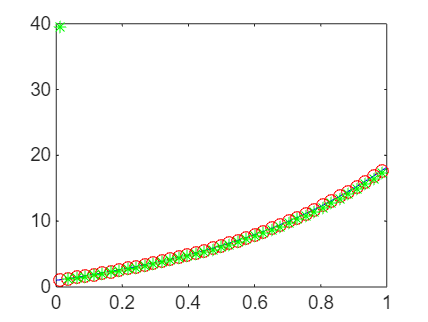

y_der = polyval(polyder(ppp),x);
xmean = (x(1:end-1) + x(2:end))/2;
plot(x,y_der,"b",xmean,D*y/h,"or",xmean,Dsym*y/h,"*g")

#### Почему для расчета производной по времени не годится центральная производная?

Центральная производная дает нам производную в $m$- й веремени, а обратная производная - производную в m+1, таким образом:

$\frac{3T^{m+1}_n - 4T^{m}_n + T^{m-1}_n }{2\Delta t}  \approx \frac {\partial T}{\partial t}_n^{m+1}$  - производная в $m+1$ - й  момент времени

$\frac{T^{m+1}_n -  T^{m-1}_n }{2\Delta t}  \approx \frac {\partial T}{\partial t}_n^{m}$ - производная в $m$ - й момент времени

Теперь посмотрим на оператор второй производной:

$\[
\frac{\partial^2 T}{\partial x^2}_{m+1,n} \approx \frac{T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}}{\Delta x^2}
\]$ - 


$$\[
D^2 = \frac{1}{\Delta x^2}
[\matrix{
-2 & 1 & 0 & \cdots & 0 \cr
1 & -2 & 1 & \cdots & 0 \cr
0 & 1 & -2 & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & 1 \cr
0 & 0 & 0 & 1 & -2
}
]$$


Тут можно обратить внимание, что так как у нас есть два индекса - один соотвествует координате, а другой  - времени, то возможны явная и неявная схемы. 

В явной схеме температуры на следующем шаге по времени выражаются через температуры на текущем шаге по времени (m+1 стоит  слева, а m - справа в рекурентном соотношении для дифференциального оператора), в неявных схемах m+1 стоит  и слева, и справа .

Построим сетку для координаты и времени:


$$x_n = (n-1)\Delta x, n\in 1...N$$
 


$$t_m = (m-1)\Delta t, m\in 1...M$$
 

Задача состоит в том, чтобы после замены дифференциальных операторов конечно-разностными, распределение температуры по толщине образца в $m+1$-й момент времени, можно было выразить через распределение температуры в $m$ - й момент времени. 


$$
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2$$
         

В данном уравнении справа у нас есть два члена:

первый - линейный дифференциальный оператор второго порядка  - вторая производная по координате 

второй - квадратичный, для дискретизации можно, вообще говоря использовать разные варианты. 

Вначале рассмтрим первый член правой части (линейный), для дискретизации можно использовать **явную** схему, **неявную** схему и схему **Кранка-Николсона** (комбинацию двух вариантов)

**Явная** схема дискретизации:

$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx \frac{T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1}}{\Delta x^2}
\]$ - явная (explicit) схема дискретизации, производная считается для m-го момента времени.

**Неявная** схема дискретизации:

$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx \frac{T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}}{\Delta x^2}
\]$ - неявная (implicit) схема дискретизации, так как для расчета производной координате используется (m+1)-й момент времени


$$\[
\frac{\partial^2 T}{\partial x^2}_{mn} \approx\frac{1}{\Delta x^2} [ \theta (T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1})+ (1 - \theta)(T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1})]
\]$$


**Кранк-Николсон:**


$$\theta=1/2$$


Для производной по времени, стоящей слева может быть использовано выражение как второго, так и первого порядка точности.

### Различные схемы и их особенности

Вначале будем рассматрицать чисто конечно-разностные схемы без привязки к граничным условиям, следовательно во всех рассуждениях данного раздела первые и последние строки матриц, а также правой части выражений будут "не верными", их нужно будет потом модифицировать под конкретные граничные условия.


$$
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2$$
         

$F_{n}^m = \frac{a_{n}^m\Delta t}{\Delta x^2$ - число Фурье

 $\phi_{n}^m  = \frac{{\lambda '}_n^m}{4\lambda_n^m}$ - коэффициент нелинейной части ($\phi = \frac{1}{4} \frac {d}{dT} (ln(\lambda(T) |_{T=T_{mn}}$)

Какие есть основные моменты относительно уравнения:

- Производная по времени (левая часть уравнения) различные формы обратной производной (BDF1, BDF2, BDF3...)

- Момент времени аппроксимации второй производной (явная m,неявная m+1, Кранк-Николсон)

- Момент времени для нелинейной части (m или m+1)

- Момент времени расчета теплофизических свойств (m или m+1)

1 - Самая простая явная схема, обладает условной сходимостью

2 - Неявная схема обладает, обладает безусловной сходимостью

3 - Схема Кранка-Никлсона (сердняя между явной и неявной) дает относительно "дешево" аппроксимацию второго порядка по времени

4 - Схема второго порядка сходимости по времени и координате, второй порядок по времени достигается использованием обратного дифференцирования BDF2.

5 - Схема второго порядка, исопльзующая как схему Кранка-Николсона, так и BDF2 для аппроксимации производной по времени

6 - Сочетает в себе обратное дифференцирования, Кранка-Николсона и неявную схему для нелинейного члена, в этом случае для вычисления распределения температуры в $m+1$-й момент времени, из-за того, что неизвестная $T^{m+1}$сходит под квадратом, теперь нужно пользоваться численным методом решения системы нелинейных уравнений (например, методом Ньютона-Рафсона)

7 - Тоже самое, что и пункт 5, но теперь все свойства также рассчитываются для m+1 - го шага

Далее получим матричные выражения для приведенных в таблице разностных схем.

Заголовки схем будут даваться по принципу: 

**тип производной по времени - тип второй производной - тип нелинейной части**

#### Схема 1. BFD1 - explicit - explicit

Это самая простая схема, слева стоит аппроксимация производной первого порядка, производная второго порядка аппроксимируется явной схемой и нелинейный член выражается через цетральную явную производную. Температура в $m+1$- й момент времени входит столько в обратную производную, то распределение температуры на следующем шаге можно получить в "одно действие"


$$(T^{m+1}_n - T^{m}_n) = F_n^m[T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1}] +F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$T^{m+1}_n =F_n^mT^{m}_{n+1} +(1-2F_n^m) T^{m}_n + F_n^mT^{m}_{n-1} + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$


Это выражение можно записать в матричной форме.

Пусть у нас есть вектор- столбец распределения температуры по толщине в текущий момент времени $\vec{T}^m$, тогда распределение температур в следующий момент времени, выражается через сумму линейной и нелинейной компонент:

$\vec{T}^{m+1} = A^m\vec{T}^m + \vec{b}^m$                                                                                    (2)

где


$$
{A}^m = [
\matrix{
1 - 2F_1^m & F_1^m & 0 & \cdots & 0 \cr
F_{2}^m & 1 - 2F_{2}^m & F_{2}^m & \cdots & 0 \cr
0 & F_{3}^m & 1 - 2F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & 1 - 2F_{N-1}^m & F_{N-1}^m \cr
0 & 0 & 0 & F_{N}^m & 1 - 2F_{N}^m
}
]$$


$A^m$ - трехдиагональная матрица


$$[\vec{b}^m(\vec{T}^m)]_n= F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$


Индекс  $n$ у нас меняется от 1 до N поэтому не понятно пока, как правильно получить выражения для первой и последней строки матрицы $A^m$ и для первого и последнего элемента вектора $\vec{b}^m$.

Данная схема наызвается явной, так как выражение (2) не требует инвертирования матрицы, выражение получается просто умножением матрицы на вектор распределения температур в предыдущий момент времени.

#### Граничные условия для схемы 1.

С начальным условием все более-менее понятно, оно дает нам вектор  $\vec{T}^1$ 

Если заданы граничные условия Дирихле, то есть, зависимость температуры сверху от времени в виде некоторой функции времени, то  $T_1^m = f(t_m) = f^m$

Чтобы сохранить вид матрицы  $A^m$ мы должны модифицировать вектор  $\vec{b}^m$ таким образом, чтобы решение соотвествовало $f^m$

$f^{m+1} =(1-2F_1^m) f^{m} + F_1^m T^{m}_{2} + b_1^m$ что дает

 
$$b_1^m = f^{m+1} -(1-2F_1^m) f^{m} - F_1^m T^{m}_{2}$$


clearvars
lam_pars =[-0.000002,0.003,4.84];
lam_fun = @(T)polyval(lam_pars,T);
lam_der = @(T)polyval(polyder(lam_pars),T);
plot(linspace(200,1000,30),lam_fun(linspace(200,1000,30)))
plot(linspace(200,1000,30),lam_der(linspace(200,1000,30)))

dt = 0.1;
T1 = transpose(100:1:1000);
Cp = 1000; Ro = 1;
dx = 0.1e-3;

`b_1^m = f^{m+1} + F_1^m (f^m - T_2^m) + F_1^m ϕ_1^m (f^m - T_3^m)^2 `

`b_2^m = F_2^m ϕ_2^m (T_1^m - T_3^m)^2 + F_2^m f^{m+1}    ← Includes T_1^{m+1} = f^{m+1}`

#### Устойчивость конечно-разностной схемы на примере явной схемы

Немного про устойчивость разностных схем, в общем случае, в особенности для достаточно сложных уравнений это целая наука, но общую идею можно проиллюстрировать для простого случая решения линейного уравнения (если теплопроводность от температуры не зависит, то вектор $\vec{b}^m$ будет равен нулю, а матрица $A^m =A$ будет постоянной. 

Ну и сетка постоянна, и число шагов по координате равно числу шагов по времени (то есть матрица $A^m$ будет кадратной). И есть известное начальное распределение температуры по толщине, тогда распределение температуры по толщине в последующие моменты времени будет даваться:


$$\vec{T}^2 = A\vec{T}^1$$
        


$$\vec{T}^3 = AA\vec{T}^1$$
 


$$\vdots$$


$\vec{T}^{k+1} = A\cdot \dots \cdot A\vec{T}^1 = [A]^{k}\vec{T}^1$  - распределение температуры в k-й момент времени

$[A]^{k}$ - умножение матрицы саму на себя k раз.

 Разложим матрицу в спектр:

$A = U\Lambda U^{-1}$, $U$ - матрица собственных векторов, $\Lambda$ - диагональная матрица собственных значений. Тогда для степени матрицы:

$[A]^{k} = U\Lambda U^{-1} \cdot \dots \cdot U\Lambda U^{-1} = U\Lambda^k U^{-1}$ - то есть, степень матрицы имеет те же собственные вектора, что и исходная 

В нашем случае матрица симметрична, поэтому собственные вектора являются ортонормированными, тогда:


$$[A]^{k} = U\Lambda^k U^{-1} = U\Lambda^k U^T = \Sigma_{i=1}^N \lambda_i^k\vec{u}_i\vec{u}_i^T$$


Из данного выражения видно, что если в спектре собственных значений матрицы $A$ есть те, которые больше 1, то вклад от них будет экспоненциально возрастать и схема станет неустойчивой. 

Таким образом, схема будет устойчивой (для линейного конечно-разностного оператора), если все собственные значения лежат в интервале от -1 до 1.

Для трехдиагональных матриц тёплица размером $N \times N$, у которых на главной диагонале стоят постоянные значений:

 $a$ -  на минус-первой 

$b$ -  на плюс первой 

 $c$ - на минус первой

Собственные значения даются аналитической [формулой](https://en.wikipedia.org/wiki/Tridiagonal_matrix):


$$\lambda_i = a -2 \sqrt {bc}cos(\frac{i\pi}{ (N+1)})$$


Или для нашего конкретного случая:


$$\lambda_i = (1 - 2F) -2Fcos(\frac{i\pi}{ (N+1)})$$


Отсюда, из условия , что все собственные значения должны быть меньше или равны единице, поулчаем:

$-1 \le (1 - 2F) -2Fcos(\frac{i\pi}{ (N+1)}) \le 1$ для $\forall \ i \in 1...N$


$$F \le 1/2$$


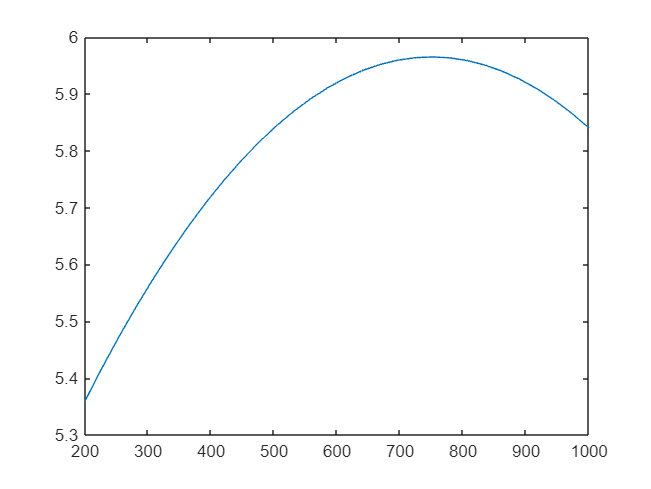

clearvars
N = 49
F = 1.806
A = toeplitz([1-2*F,F,zeros(1,N-2)]);
e = eig(A);

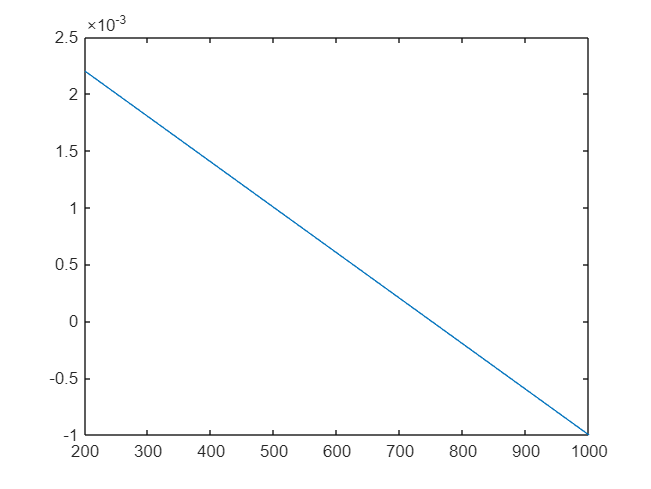

y = (1-2*F)  - 2*F*cos((1:N)*pi/(N+1));

plot(e,"o")
hold on
plot(y,"LineWidth",2)
hold off
legend(["eig(А)","(1-2F) - 2*F*cos(k\pi/(N+1)"],"Location","best")
xlabel("i");ylabel("\lambda_i")
title("Собственные значения матрицы А")
% теперь посмотрим на то как будет расти норма матрицы 
% по мере решения линейного дифура
An = eye(size(A));
nrm = zeros(size(y));
for ii = 1:N
    An = A*An;
    nrm(ii) = norm(An,"fro");
end
plot(nrm)
yscale("log")
title("Норма матрицы A^n")
xlabel("n")
ylabel("||A^n||")


#### Схема 2. BFD1 - implicit - explicit

Производная по времени обратное дифференцирование, первого порядка, чисто неявная схема для второй производной по координате, явная схема для аппркосимация производной в нелинейной части, свойства берутся на с предыдущего момента времени.


$$(T^{m+1}_n - T^{m}_n) = F_n^mT^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}] + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$
{B}_m = [
\matrix{
1 + 2F_{m1} & -F_{m1} & 0 & \cdots & 0 \cr
-F_{m2} & 1 + 2F_{m2} & -F_{m2} & \cdots & 0 \cr
0 & -F_{m3} & 1 + 2F_{m3} & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -F_{m,N-1} \cr
0 & 0 & 0 & -F_{mN} & 1 + 2F_{mN}
}
]$$


Вектор $\vec{b}^m$ - нелинейная функция (квадратичная) такая же, как и в схеме 1

Таким образом неявная схема решения свелась к системе линейных уравнений для нахождения распределения температуры по толщине в следующий момент времени через предыдущие:


$$B_m\vec{T}^{m+1} =\vec{T}^m + \vec{b}^m$$


#### Схема 3. BFD1 - CN - explicit

Отличается от предыдущий исопльзованием схемы Кранка-Николсона для аппроксимации второй производной, что дает второй порядок точности по времени


$$(T^{m+1}_n - T^{m}_n) =\frac{1}{2} (F_n^m[T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}]) + \frac{1}{2} (F_n^m[T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1}])   + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$-\frac{1}{2}F_n^mT^{m+1}_{n+1} + T^{m+1}_n (1 + F_n^m ) -\frac{1}{2} F_n^mT^{m+1}_{n-1} =\frac{1}{2}F_n^m T^{m}_{n+1} +  T^{m}_n(1 -  F_n^m) + \frac{1}{2}F_n^mT^{m}_{n-1}   +F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$


В матричной форме это имеет вид:


$$C^m\vec{T}^{m+1} = N^m\vec{T}^m + \vec{b}^m$$


$
{C}^m = [
\matrix{
1 + F_{1}^m & - \frac{1}{2}F_{1}^m & 0 & \cdots & 0 \cr
-\frac{1}{2}F_{2}^m & 1 + F_{2}^m & -\frac{1}{2}F_{2}^m & \cdots & 0 \cr
0 & -\frac{1}{2}F_{3}^m & 1 + F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -\frac{1}{2}F_{N-1}^m \cr
0 & 0 & 0 & -\frac{1}{2}F_{N}^m & 1 + F_{N}^m
}
]$,

Вторая матрица также трехдиагональная


$$
N^m = [
\matrix{
1 - F_{1}^m & \frac{1}{2}F_{1}^m & 0 & \cdots & 0 \cr
\frac{1}{2}F_{2}^m & 1 - F_{2}^m & \frac{1}{2}F_{2}^m & \cdots & 0 \cr
0 & \frac{1}{2}F_{3}^m & 1 - F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & \frac{1}{2}F_{N-1}^m \cr
0 & 0 & 0 & \frac{1}{2}F_{N}^m & 1 - F_{N}^m
}
]$$
 

Вектор $\vec{b}^m$ - нелинейная функция (квадратичная) такая же, как и в схеме 1

#### Схема 4.BFD2 - implicit - explicit

Данная схема имеет ту же точность, что и предыдущая, но при этом использует полную неявную схему для второй производной и обратную производную второго порядка (**BFD2**).


$$\frac{3}{2}T^{m+1}_n - 2T^{m}_n + \frac{1}{2}T^{m-1}_n  =F_{n}^m[T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}] + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$ - F_{n}^mT^{m+1}_{n+1} +[\frac{3}{2} + 2 F_{n}^m] T^{m+1}_n  - F_{n}^mT^{m+1}_{n-1}  = 2T^{m}_n -\frac{1}{2}T^{m-1}_n  + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$P^m\vec{T}^{m+1} = 2\vec{T}^m - \frac{1}{2}\vec{T}^{m-1} + \vec{b}^m$$



$$
{P}^m = [
\matrix{
\frac{3}{2} + 2F_{1}^m& - F_{1}^m  & 0 & \cdots & 0 \cr
-F_{2}^m & \frac{3}{2} + 2F_{2}^m & -F_{2}^m & \cdots & 0 \cr
0 & -F_{3}^m & \frac{3}{2} + 2F_{3}^m & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & -F_{N-1}^m \cr
0 & 0 & 0 & -F_{N}^m & \frac{3}{2}+ 2F_{N}^m
}
]$$


Вектор $\vec{b}^m$ - нелинейная функция (квадратичная) такая же, как и в схеме 1. Ключевым отличием данной схемы от схемы 2

#### Схема 5. BFD2 - СN - explicit

Данная схема имеет ту же точность, что и предыдущая, но при этом использует схему Кранка-НИколсона для второй производной и обратную производную второго порядка (**BFD2**).

Левая часть тут получится такойже, как и у предыдущей схемы, а правая часть - похожа на схему 3, но с некоторыми модификациями


$$\frac{3}{2}T^{m+1}_n - 2T^{m}_n + \frac{1}{2}T^{m-1}_n  =\frac{1}{2} (F_{nm}[T^{m+1}_{n+1}  - 2T^{m+1}_{n} +T^{m+1}_{n-1}]) + \frac{1}{2} (F_{nm}[T^{m}_{n+1}  - 2T^{m}_{n} +T^{m}_{n-1}]) + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$-\frac{1}{2} F_{nm}T^{m+1}_{n+1} +[\frac{3}{2} + F_{nm}] T^{m+1}_n  - \frac{1}{2}F_{nm}T^{m+1}_{n-1} = \frac{1}{2}F_{nm}T^{m}_{n+1} +  T^{m}_n(2 - F_{nm}) + \frac{1}{2}F_{nm}T^{m}_{n-1}   -\frac{1}{2}T^{m-1}_n  + F_{n}^m \phi_{n}^m (T^{m}_{n-1} - T^{m}_{n+1})^2$$



$$P^m\vec{T}^{m+1} = Q^m\vec{T}^m - \frac{1}{2}\vec{T}^{m-1} + \vec{b}^m$$



$$Q^m = [
\matrix{
2 - F_{m1} & \frac{1}{2}F_{m1} & 0 & \cdots & 0 \cr
\frac{1}{2}F_{m2} & 2 - F_{m2} & \frac{1}{2}F_{m2} & \cdots & 0 \cr
0 & \frac{1}{2}F_{m3}` & 2 - F_{m3} & \cdots & 0 \cr
\vdots & \vdots & \vdots & \ddots & \frac{1}{2}F_{m,N-1} \cr
0 & 0 & 0 & \frac{1}{2}F_{mN} & 2 - F_{mN}
}
]$$


Вектор $\vec{b}^m$ - нелинейная функция (квадратичная) такая же, как и в схеме 1, матрица $D^m$ такая же, как  в схеме 4

#### Схема 6. BFD2 - СТ - implicit

Схема практически полностью аналогична предыдущей, однако имеет существенной отличие, которое требует другого решателя системы уравнений!

для производной по времени - обратное дифференцирование второго порядка, для второй производной - схема К-Н, при этом для аппроксимации производной в нелинейной части теперь используется **неявная** схема!  


$$P^m\vec{T}^{m+1} = Q^m\vec{T}^m - \frac{1}{2}\vec{T}^{m-1} + \vec{b'}^{m+1}(\vec{T}^{m+1} )$$


$\vec{b'}^{m+1}_n =F_{n}^m\phi_{n}^{m}(T_{n+1}^{m+1} - T_{n-1}^{m+1})^2$ - в нелинейной части, физические свойства берутся из $m$ - го момента времени, а вот производная по координате считается уже в неявном виде, поэтому вектор $\vec{b'}$ зависит от  $\vec{T}^{m+1}$ относительно просто.

Это уже система нелинейных уравнений, так как неизвестный вектор $\vec{T}^{m+1}$ сходит в правую часть в виде квадратичной функции. 

Для решения системы нелинейных уравнений может быть исопльзован метод Ньютона-Рафсона.

#### Метод Ньютона-Рафсона

Если у нас есть система нелинейных уравнений:

$\vec{\Phi}(\vec{x})=\vec{0}$ , где $\vec{\Phi}$ - нелинейная векторная функция векторного аргумента, которая осуществляет взамно-однозначный мэппинг, такой, что $\vec{\Phi}: \mathcal{R}^N \to \mathcal{R}^N$, итерация методу Н-Р:


$$\vec{x}_{k+1} = \vec{x}_k - [\nabla\vec{\Phi}(\vec{x}_k)]^{-1}\vec{\Phi}(\vec{x}_k)$$


$k$ - индекс шага

$\nabla \vec{\Phi}(\vec{x}_k) = J(\vec{x}_k)$ - матрица Якоби (градиент вектора).

Метод следует опять-таки из разложения векторной функции в ряд Тейлора:


$$\vec{\Phi}( \vec{x} + \vec{p}) = \vec{\Phi}(\vec{x}) +  \nabla\vec{\Phi}(\vec{x})(\vec{p} ) +\frac{1}{2!}\vec{p}^T \nabla^2 \vec{\Phi}(\vec{x})\vec{p} + ... $$



$$\vec{\Phi}( \vec{x}_k) = \vec{\Phi}(\vec{x}^*) +  \nabla\vec{\Phi}(\vec{x}^*)(\vec{x}_k - \vec{x}^* ) + O(||x^* + x_k||^2) =  \nabla \vec{\Phi}(\vec{x}^*)(\vec{x}_k - \vec{x}^* ) + O(||x^* + x_k||^2)$$


Подставив в формулу для шага:


$$\vec{x}_{k+1} - \vec{x}^* = \vec{x}_k - \vec{x}^*  - [\nabla\vec{\Phi}(\vec{x}_k)]^{-1} [\nabla \vec{\Phi}(\vec{x}^*)(\vec{x}_k - \vec{x}^* ) + O(||x^* + x_k||^2)]$$


#### Применение метода Ньютона-Рафсона для схемы 6

Для применения метода Ньютона-Рафсона к схеме BFD2 - СТ - implicit, выражение перепишем в виде системы нелинейных уравнений, чтобы решать их мтеодом Ньютона-Рафсона:


$$\vec{\Phi}(\vec{X})=P^m\vec{X} -  \vec{b'}(\vec{X}) + \frac{1}{2}\vec{T}^{m-1} - Q^m\vec{T}^m = \vec{0}$$


Неизвестным тут является вектор $\vec{X} \equiv \vec{T}^{m+1}$

Чтобы итерационно решать систему $\vec{\Phi}(\vec{X})= \vec{0}$необходимо уметь вычислять матрицу якоби $\nabla_{\vec{X}}\vec{\Phi}$, 

в выражении для $\vec{\Phi}$ первые два слагаемых зависят от неизвестной (распределения температуры по толщине на следующем шаге),

а вторые два слагаемых - только от известных температур в предыдущие моменты времени.

В данном случае, матрица якоби задачи может быть достаточно просто посчитана аналитически. 

Для первого слагаемого все просто: 


$$\nabla_{\vec{X}}[P^m\vec{X}] = P^m$$


Для второго слагаемого ситуация сложнее:

Формулу для вектора $\vec{b'}$ можно переписать в матричном виде (первая и последняя строки этой матрицы - неправильные, так как зависят от типа граничных условий):


$$\[
D =[
\matrix{
0 & -1 & 0 & \cdots & 0 \cr
1 & 0 & -1 & \cdots & 0 \cr
\vdots & & \ddots & \ddots & \vdots \cr
0 & \cdots & 1 & 0 & -1 \cr
0 & \cdots & \cdots & 1 & 0
}
]$$


$\vec{b'}(\vec{X})= \mathrm{diag}(\vec{F}^{m}\circ\vec{\phi}^{m})(D\vec{X}\circ D\vec{X})$  , где $\vec{F}^m = \matrix{ F_1^m \cr \vdots \cr F_N^m}$ , $\vec{\phi}^m = \matrix{ \phi_1^m \cr \vdots \cr \phi_N^m}$

 $\circ$ - поэлементное умножение (произведение Адамара) $\vec{c}(\vec{x}) = \vec{a} \circ \vec{b}$ : $[\vec{c}]_i = [\vec{a}]_i[\vec{b}]_i$ : $\vec{c} =[ \matrix{a_1b_1 \cr \vdots \cr a_n b_n}]$

$\mathrm{diag}(\vec{a})$ - операция диагонализации вектора, $\mathrm{diag}(\vec{a}) = [ \matrix{a_1 & \dots &0\cr 0&\ddots & 0\cr 0 & \dots & a_N  }]$

Операция  $\mathrm{diag}(\vec{a})A$ умножает каждую строку матрицы на соответствующую координату вектора $\vec{a}$, если умножать матрицу справа $A\cdot \mathrm{diag}(\vec{a})$ на диагонализованный вектор, то каждый столбец матрицы умножается на соотвествующую координату

clearvars
a = sym('a',[3,1]);

N = 49

b = sym('b',[2,1]);

F = 1.8060

C = sym('c',[3,2]);
diag(a)*C
C*diag(b)
% в матлаб произведение адамара работает добавлением точки 
a.*C
C.*transpose(b)


 Так как вектор $\vec{b'}(\vec{x})$ содержит произведение Адамара двух векторов, то вначале получим формулу для дифференцирования произведения Адама двух векторных функций, зависящих от векторного аргумента. 

$\vec{c}(\vec{x}) = \vec{a}(\vec{x}) \circ \vec{b}(\vec{x})$  $\vec{c} =[ \matrix{a_1 (\vec{x}) b_1(\vec{x}) \cr \vdots \cr a_n(\vec{x}) b_n (\vec{x})}]$, тогда 


$$\nabla_{\vec{x}}\vec{c} = [\matrix{
 \nabla [ a_1 (\vec{x}) b_1(\vec{x}) ]\cr
 \vdots \cr
 \nabla[a_n(\vec{x}) b_n (\vec{x})]}] =  [\matrix{
 \nabla [ a_1 (\vec{x})] b_1(\vec{x}) \cr
 \vdots \cr
 \nabla[a_n(\vec{x})] b_n (\vec{x})}]  + [\matrix{
 a_1 (\vec{x}) \nabla [ b_1(\vec{x}) ]\cr
 \vdots \cr
a_n(\vec{x})  \nabla[b_n (\vec{x})]}]  = \mathrm{diag}(\vec{b})\nabla\vec{a} + \mathrm{diag}(\vec{a})\nabla\vec{b}$$


То есть, градиент вектора (матрица Якоби) произведения Адамара двух векторных функций - это сумма  матриц Якоби этих вух функции, в которых каждая строка умножена на соотвествующую координату второй функции. 

В соответствии с этим выражением легко получить формулу для матрицы Якоби вектора $\vec{b'}(\vec{x})$:


$$\nabla_{\vec{X}} \vec{b'}(\vec{X})= \nabla [\mathrm{diag}(\vec{F}_{m}\circ\vec{\phi}_{m})(D\vec{X}\circ D\vec{X})] = 
\mathrm{diag}(\vec{F}_{m}\circ\vec{\phi}_{m}) \nabla [(D\vec{X}\circ D\vec{X})] = 
\mathrm{diag}(\vec{F}_{m}\circ\vec{\phi}_{m}) [\mathrm{diag}(D\vec{X})\nabla[D\vec{X}]   + D\vec{X})\nabla[D\vec{X}] ] = 
2\mathrm{diag}(\vec{F}_{m}\circ\vec{\phi}_{m} \circ (D\vec{X}))D$$
 

Итого, окончательное выражение для $k$-й итерации метода Ньютона-Рафсона для схемы **BFD2 - СТ - implicit **будет иметь вид:


$$\vec{\Phi}(\vec{X}_k)=P^m\vec{X}_k -  \vec{b'}(\vec{X}_k) + \frac{1}{2}\vec{T}^{m-1} - Q^m\vec{T}^m$$



$$\nabla \vec{\Phi}(\vec{X}_k)= P^m + 2\mathrm{diag}[\vec{F}^{m}\circ\vec{\phi}^{m} \circ (D\vec{X}_k)]D$$



$$\vec{X}_{k+1} = \vec{X}_k - (\nabla \vec{\Phi}(\vec{X}_k))^{-1}\vec{\Phi}(\vec{X}_k)$$


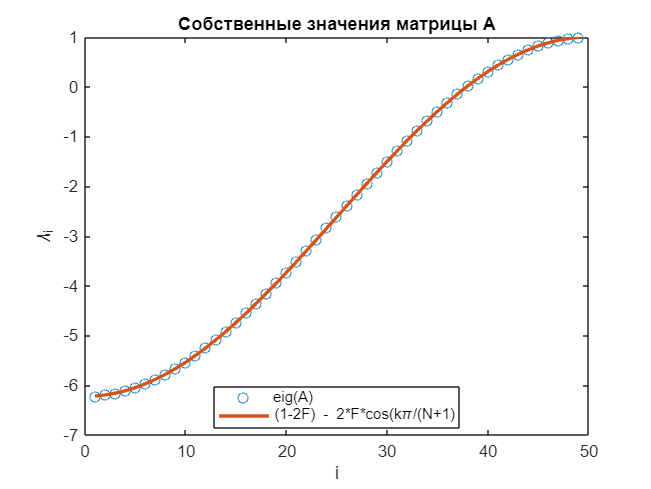

syms x1 x2 real
A = sym('a',[2,2]);
jacobian(A*[x1;x2],[x1;x2])

F = A*[x1;x2] .* A*[x1;x2];
J = jacobian(F, [x1 x2])


#### Схема 6. BFD2 - СТ - implicit  + implicit material properties

Эта схема отличается от предыдущей тем, что материальные свойства тоже берутся в неявной форме, то есть:


$$P^{m+1}\vec{T}^{m+1} = Q^{m+1}\vec{T}^m - \frac{1}{2}\vec{T}^{m-1} + \vec{b}^{m+1}(\vec{T}^{m+1} )$$


Теперь мы не только считаем производные для $m+1$ -го момента времени, но и теплофизические свойства рассчитываем из неявной схемы.

$b_n^{m+1} = F_{n}^{m+1}\phi_{n}^{m+1}(T^{m+1}_{n-1} - T^{m+1}_{n+1})^2$ , также и все матрицы теперь тоже зависят от распределения температуры для $m+1$ -го момента времени


$$\vec{b}(\vec{T}^{m+1})= \mathrm{diag}(\vec{F}^{m+1}\circ\vec{\phi}^{m+1})(D\vec{T}^{m+1}\circ D\vec{T}^{m+1}})$$


Функция невязки для метода Ньютона-Рафсона будет иметь вид:

$\vec{\Phi}(\vec{X})=P(\vec{X})\cdot\vec{X} -  \vec{b}(\vec{X}) + \frac{1}{2}\vec{T}^{m-1} - Q(\vec{X})\vec{T}^m$ - матрицы $P$ и $Q$ теперь являются функциями неизвестной переменной $\vec{X} \equiv \vec{T}^{m+1}$

### Граничные условия

С начальным условием все более-менее понятно, оно дает нам соотвественно первую строку матрицы $T_{n}^1$ 


$$T_n^1 = \phi(x_n)$$


В матрицах конечно-разностных схем явно что-то не так с первой и последней строками. 

Предположим, что теплофизика не зависит от температуры, а это значит, что вектор  $\vec{b}^m$ не будет иметь нелинейного члена и станет равным просто вектору$\vec{T}^m$, также для простоты, пусть сетка выбрана такой, что $F_{mn}=\frac{a_{mn}\Delta t}{\Delta x^2} = 1$ и у нас равномерное распределения температуры по толщине, такое решение должно давать тривильную форму

N = 100;
A = toeplitz([3,-1,zeros(1,N-2)])
T0 = 20*ones(N,1);
T = zeros(N);
T(:,1) = T0;
for ii=2:N
    T(:,ii) = A\T(:,ii-1);
end
surf(T)

Нам нужно, чтобы матрица при решении задачи всегда давала заданное значение первой координаты вектора  $\vec{T}^{m}$: $T_1^m(t_m) = f(t_m)= f^m$  

Как вариант  можно модифицировать матрицу $B_m$, 


$$
{B}_m  \vec{T}^{m+1}  = \vec{b}^m$$


насчет первой строки понятно, ее можно сделать тривиальной:


$$[
\matrix{
1 & 0 & 0 & \cdots & 0 \cr
-F_{m2} & 1 + 2F_{m2} & -F_{m2} & \cdots & 0 \cr
0 & -F_{m3} & 1 + 2F_{m3} & \cdots & 0 \cr
&&&\ddots&&\cr
\vdots & \vdots & F_{m,N-1} & 1 + 2F_{m,N-1} & -F_{m,N-1} \cr
0 & 0 & 0 & -F_{mN} & 1 + 2F_{mN}
}
] [ \matrix{T_1^{m+1} \cr \vdots  \cr T_N^{m+1}}]= [\matrix{b_1^m \cr \vdots \cr b_N^m}]$$


При этом мы должны поменять первую и вторую координаты вектора $\vec{b}^m$

$b_1^m =T_1^{m+1}  =  f(t_{m+1}) = f^{m+1}$,


$$b_2^m = T_2^m + F_{m2}\phi_{m2} (T_1^m - T_3^m)^2 + F_{m2}T_1^{m+1}$$


Остальные остаются без изменений, таким образом, добавление граничных условий влияет на 

непосредственно элемент сетки, куда добавляем, а также на соседний.

Однако данный способ не идеален, так как исходная матрица была трехдиагональной, а теперь стала полной, для трехдиагональных матриц существует специальный быстрый солвер (при решении системы при помощи mldivide)

Для учета граничных условий и расчета теплового потока, рекомендуется использовать разностные соотношения второго порядка точности, учитывающие накопление тепла на предыдущем шаге:

$q^{m+1}=\frac{\lambda_0^m}{\Delta x}(T_0^{m+1} - T_1^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_0^{m+1} - T_0^m) $ - тепловой поток сверху

$\tilde q^{m+1}=\frac{\lambda_N^m}{\Delta x}(T_N^{m+1} - T_{N-1}^{m+1}) + C_0^m\frac{\Delta x}{2\Delta t}(T_N^{m+1} - T_N^m) $ - тепловой поток снизу

В матричной форме данные уравнения будут иметь вид0

Рассмотрим одномерную задачу теплопроводности


$$\begin{cases} \matrix{
 C(T) \frac{\partial T}{\partial t}  = \frac{\partial }{\partial x}( \lambda(T) \frac{\partial T}{\partial x}) \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(d,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde q(t)


} \end{cases}$$


Это уравнение в частных произодных, с двумя переменными - время и координата, толщина образца $b$, $d$ - точка расположения термопары.Кроме того, мы знаем распределение температуры по толщине образца в начальный момент времени $\phi(x)$, зависимость температуры от времени на некоторой глубине $d$, которая задачется функцией $f(t)$ и зависимость от времени теплового потока через нижнюю границу $\tilde{q}(t)$.

$C(T)$ -  теплоемкость образца, она выражается через его удельную теплоемкость и плотность:$С(T) = c_v(T)\rho$. 

$\lambda(T)$ - коэффициент теплопроводности 

 Если $d=0$ - уравнение становится прямой задачей, с граничными условиями первого рода (температура) сверху и второго рода (тепловой поток) снизу. Собственно, в области $x \in [d,b]$ задача является прямой и решается однозначно. А вот в область $x \in [0,d]$ решение требуется продлить, восстановив граничные условия и температуру на верхней границе (то есть, это задача восстановления граничных условий). Задача в такой формулировке удобна, так как на практике, даже если мы ставим целью измерить температуры на поверхности слоя, термопары все равно должны заделываться на некоторую глубину под поверхностью образца, измерить температуру нагреваемой поверхности при помощи термопары невозможно.

Пусть нам известна зависимость температуры от времени сверху  и тепловой поток снизу слоя.

Предполжим, что температура у нас имеет следующую форму, это матрица $[T]$, элемент $T_l^n$ которой, стоящий на $m$ -й строке $n$ - го столбца представляет собой температуру в $m$ - й момент времени для точки с $n$ - й координатой. Данная матрциа имеет размерность $M \times N$.


$$\begin{cases} \matrix{
\frac {1}{a(T)} \frac{\partial T}{\partial t}  =\frac{\partial^2 T}{\partial x^2} +   \frac{\lambda'(T)}{\lambda(T)} (\frac{\partial T}{\partial x})^2 \cr 
T(x,0) = \phi(x),x   \in [0,b] \cr
T(0,t) = f(t), t \in [0,t_m] \cr
-\lambda(T(b,t))\frac{\partial T}{\partial x} (b,t) = \tilde {q}(t)
} \end{cases}$$


FUNTIONS

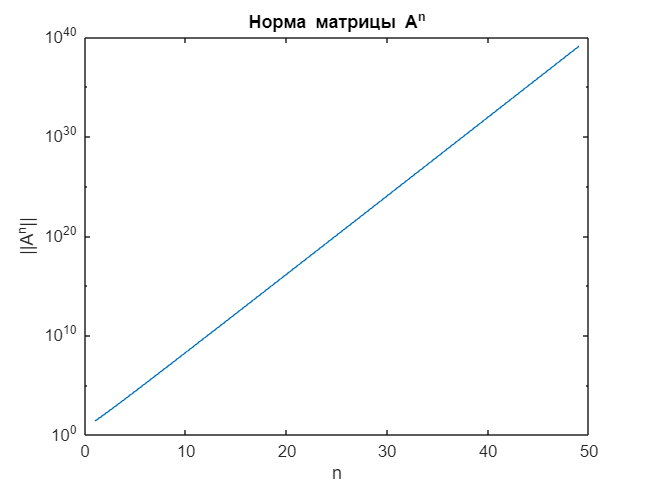

function D = Dt(M)

$$ans = \left(\begin{array}{cc} a_{1}\,c_{1,1} & a_{1}\,c_{1,2}\\ a_{2}\,c_{2,1} & a_{2}\,c_{2,2}\\ a_{3}\,c_{3,1} & a_{3}\,c_{3,2} \end{array}\right)$$

$$ans = \left(\begin{array}{cc} b_{1}\,c_{1,1} & b_{2}\,c_{1,2}\\ b_{1}\,c_{2,1} & b_{2}\,c_{2,2}\\ b_{1}\,c_{3,1} & b_{2}\,c_{3,2} \end{array}\right)$$

$$ans = \left(\begin{array}{cc} a_{1}\,c_{1,1} & a_{1}\,c_{1,2}\\ a_{2}\,c_{2,1} & a_{2}\,c_{2,2}\\ a_{3}\,c_{3,1} & a_{3}\,c_{3,2} \end{array}\right)$$

$$ans = \left(\begin{array}{cc} b_{1}\,c_{1,1} & b_{2}\,c_{1,2}\\ b_{1}\,c_{2,1} & b_{2}\,c_{2,2}\\ b_{1}\,c_{3,1} & b_{2}\,c_{3,2} \end{array}\right)$$

$$ans = \left(\begin{array}{cc} a_{1,1} & a_{1,2}\\ a_{2,1} & a_{2,2} \end{array}\right)$$

$$J = \begin{array}{l} \left(\begin{array}{cc} a_{1,1}\,\sigma_{2}+{a_{1,1}}^{2}\,x_{1}+a_{1,1}\,a_{1,2}\,x_{2} & a_{1,2}\,\sigma_{2}+{a_{1,2}}^{2}\,x_{2}+a_{1,1}\,a_{1,2}\,x_{1}\\ a_{2,1}\,\sigma_{1}+{a_{2,1}}^{2}\,x_{1}+a_{2,1}\,a_{2,2}\,x_{2} & a_{2,2}\,\sigma_{1}+{a_{2,2}}^{2}\,x_{2}+a_{2,1}\,a_{2,2}\,x_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2,1}\,x_{1}+a_{2,2}\,x_{2}\\ \sigma_{2}=a_{1,1}\,x_{1}+a_{1,2}\,x_{2} \end{array}$$

A =      3    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1     3    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     3    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     3    -1     0     0     0     0     0     0     0     0     0     0   

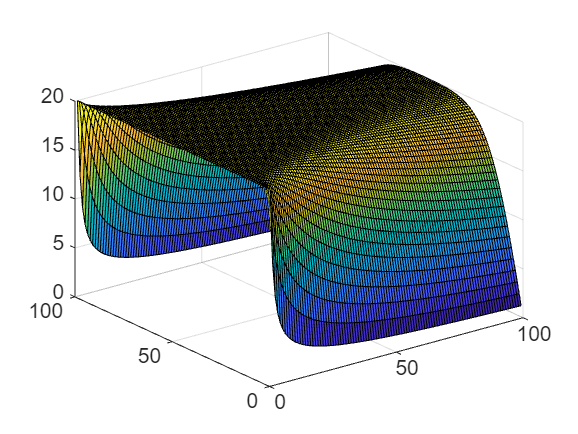

% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(0,M-1,M)) = -1;
    D(diagonal_inds(1,M-1,M)) = 1;
end
function D = Dtsym(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(-1,M-1,M)) = -1/2;
    D(diagonal_inds(1,M-1,M)) = 1/2;
end
function D = D2t(N)
    D = zeros(N,N);
    D(diagonal_inds(0,M-1,M)) = -2;
    D(diagonal_inds(1,M-1,M)) = 1; 
    D(diagonal_inds(-1,M-1,M)) = 1;
end
function indices = diagonal_inds(diagonal_index,rows_number, columns_number)
    % diagonalIndicesRect returns linear indices of the k-th diagonal of an m x n matrix
    % m - number of rows
    % n - number of columns
    % k - diagonal number (0 = main, >0 above main, <0 below main)
    %
    % Linear indices are returned for the elements along the specified diagonal,
    % respecting matrix dimensions.
    
    if diagonal_index >= 0
        % Diagonal above or on main
        len = min(rows_number, columns_number-diagonal_index);
        rowIdx = 1:len;
        colIdx = (1:len) + diagonal_index;
    else
        % Diagonal below main
        len = min(rows_number+diagonal_index, columns_number);
        rowIdx = (1:len) - diagonal_index;
        colIdx = 1:len;
    end
    
    % Convert row and column indices to linear indices for column-major order
    indices = sub2ind([rows_number columns_number], rowIdx, colIdx);
end
function t = chebyshev_nodes(n, tmin, tmax)
    % Chebyshev-Gauss-Lobatto nodes on [-1, 1]: cos(pi * (0:n-1)/(n-1))
    k = (0:n-1)';
    u = cos(pi * k / (n - 1));  % Includes endpoints u=±1
    
    % Affine map to [tmin, tmax]
    t = tmin + (tmax - tmin) * (u + 1) / 2;
end
function V = cheb_vandermonde(nodes, d)
    % CHEB_VANDERMONDE: Chebyshev basis Vandermonde (well-conditioned)
    n = length(nodes); V = zeros(n, d+1);
    V(:,1) = 1; V(:,2) = nodes;
    for k = 2:d
        V(:,k+1) = 2*nodes .* V(:,k) - V(:,k-1);  % T_k recurrence
    end
end
function [f,g] = rosen(x)
f = 100*(x(1) - x(2)^2)^2 + (1 - x(2))^2;
if nargout > 1
    g(1) = 200*(x(1) - x(2)^2);
    g(2) = -400*x(2)*(x(1) - x(2)^2) - 2*(1 - x(2));
end
end